# Post Simulation Report Generation

**This Documentation is a collection of previous work - Some Methods Might be Obsolete**

# **Model-Based Unit Testing**

The purpose of this work is to develop a model-based unit testing method in MOBATSim, which combines requirement-based testing and scenario-based testing to test model components to verify that the tested model components meet all design requirements, and the tests performed on the components are sufficient.

Based on requirement-based testing, it is necessary to first define the functional requirements of the tested model component as a standard that the model components must meet, and then isolate each tested component from the main model by creating a Test Harness Model for the tested component. By writing requirement-based assessments, the requirements are changed from a language that the machine cannot understand to a test evaluation standard that can be understood and used by the machine in the test. Based on scenario-based testing to create test inputs for the test of the component under test, each test input vector represents a specific test scenario. Use the tool Simulink Test Manager to create and manage test cases, and run test cases to execute tests. Requirement-based assessments are used to assess whether the test cases meet the requirements, and the tool Simulink Coverage is used to analyze whether the executed tests are complete. 

Here you can see the workflow of the model-based testing approach:

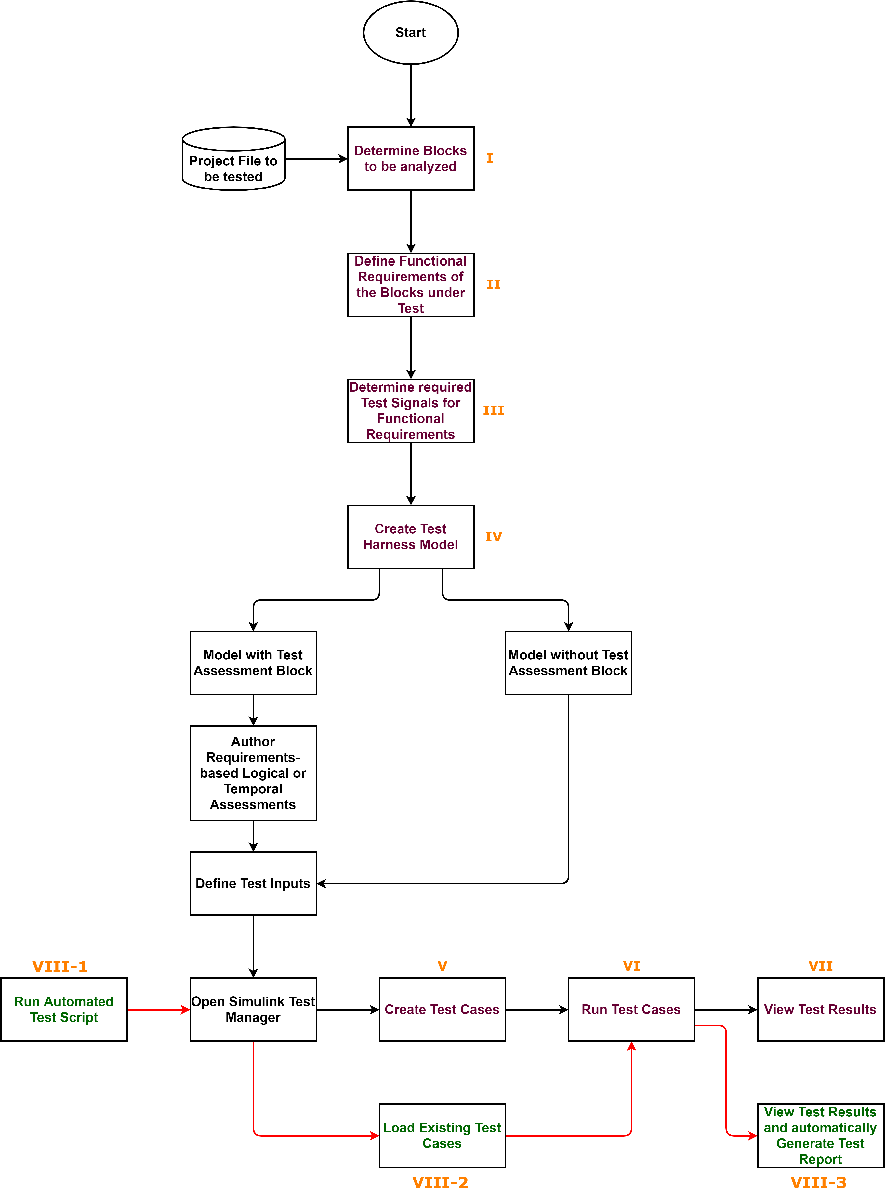

# **I. Determine Model Components under Test**

First determine the model components that need to be tested. Some specific blocks need to be modified or replaced before building the test.

## A. Individual Blocks

Individual blocks are single model components, which does not contain other simulink blocks.

### 1. MATLAB System Blocks

System objects let you implement algorithms using the MATLAB language. The [MATLAB System](https://www.mathworks.com/help/simulink/slref/matlabsystem.html) block enables you to use System objects in Simulink.

In our test method, we need to use the tool **Simulink Coverage** to evaluate the test completeness  in the test of model components, and for MALTAB System blocks, **Simulink Coverage** cannot perform model analysis for MATLAB System block with **Simulate using** parameter set to **Interpreted execution**. In our model, that happens to be the case:

Therefore, in order to be able to use **Simulink Coverage** to evaluate the test coverage of all tested components, it is necessary to convert the tested MATLAB System blocks into other types of blocks and then perform the test. Here, we choose to convert **MATLAB System blocks** into **Stateflow Charts**.

To go back to Table of Contents

### 2. Simulink Blocks

These blocks are single simulink blocks in the Block Libraries.

## B. Composed Blocks

In our model, such composed blocks are the subsystem blocks that contain some simulink blocks in the Block Libraries.

# **II. Define Functional Requirements**

The purpose of testing here is to verify that the designed model or model components meet our design requirements or industry standards. To this end, you must first define functional requirements for the test of the model, and specify which requirements each model component under test needs to satisfy. The requirements of each tested model component are regarded as the design specifications of the component.

The tool **Simulink Requirements** lets you author, analyze, and manage requirements within Simulink. With **Simulink Requirements**, you can create requirements with custom attributes and link them to model components, code, and tests. You can also analyze requirements traceability, and navigate between requirements, model components, generated code, and tests.

If you are in the project folder, run the code below to go to the folder of Model-based Testing:

cd(strcat(pwd,'\src\Misc\ModelBasedTesting'))

For more detailed information about Simulink Requirements, please click [here](https://www.mathworks.com/help/slrequirements/index.html?s_tid=CRUX_lftnav).

To go back to Table of Contents

## **A. Analyze Model/Block Structure**

Analyze the structure of the tested block to determine the role of the block and all the functions implemented by the block. All restrictions and all functions of the tested block are used to define functional requirements.

To go back to Table of Contents

## **B. Create Requirements**

A requirement is a text format described in natural language and does not contain logic that can be understood by machines. A requirement specifies a function/condition that the corresponding block needs to satisfy. You can add detailed text, images, and keywords to describe a requirement. 

You can create a new requirement set and its requirements in the Requirements Editor or Requirements Browser.

To go back to Table of Contents

### 1. Requirements Editor

The Requirements Editor can be used to create and manage all requirement sets and their requirements.

On the main model interface, click **APPS** in the upper menu bar, then click **Requirements Manager** in the options below.  In the **Requirements** tab, click **Requirements Editor** to open the editor.

You can also use the following code to directly open the Requirements Editor:

%Open Requirements Editor
slreq.editor

You can directly run the following code to open an existing requirements set:

%Open the existing requirements set
slreq.open('export_Requirements_MOBATSim')

- From the Requirements Editor toolbar, click **New Requirement Set **to create a new requirement set:

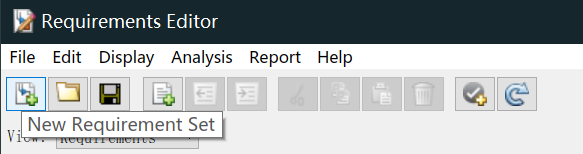

You can also use the following code to create a new requirement set:

%creates a requirement set named reqSetName in the current working folder
newReqSet1 = slreq.new(reqSetName)

%creates a requirement set on the specified path
%newReqSet2 = slreq.new(reqSetPath)

When you create a new requirement set, a requirements data file with the suffix "`.slreqx`" will be generated. 

In our example, the existing requirements data file is named "`export_Requirements_MOBATSim.slreqx`".

- Click **Display** in the menu bar, and select all the options in the **Display** drop-down menu to view different information in Requirements Editor, especially "**Implementation Status**" and "**Verification Status**":

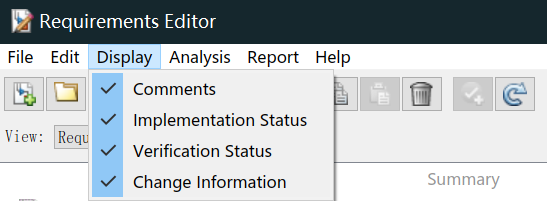

"**Implementation Status**" shows whether this requirement is linked to the block that implements it.

"**Verification Status**" shows whether this requirement is linked to the test case used to verify it.

More detailed information will be provided in the following sections.

- Right click on the newly created requirement set to add a new requirement, and then click on the newly created requirement, you can author your requirements by writing the content, ID, summary etc. in the** Properities** tab displayed on the right:

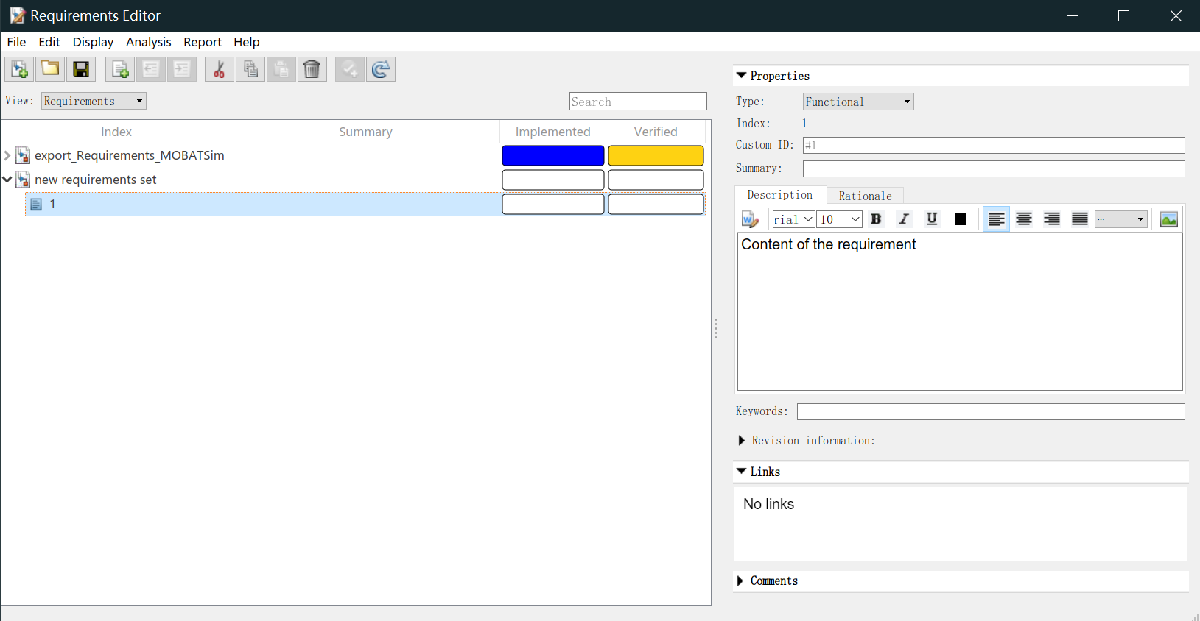

As you can see in the figure above, the content in tab **Links** is empty, and the requirement has not been linked to any other components. When the selected requirement is linked to other components, the link information between the requirement and other components will be displayed here.

To go back to Table of Contents

### 2. Requirements Browser

The **Requirements Browser** is similar to the aforementioned **Requirements Editor**. Both are used to create and manage requirement sets and their requirements. The requirements created in these two tools are compatible with each other and can be opened directly in another tool.

- In the slimulink model interface, click the icon** Show Perspectives views** in the lower right corner, and then click **Enter Perspective Requirements** to enter the Requirements Perspective:

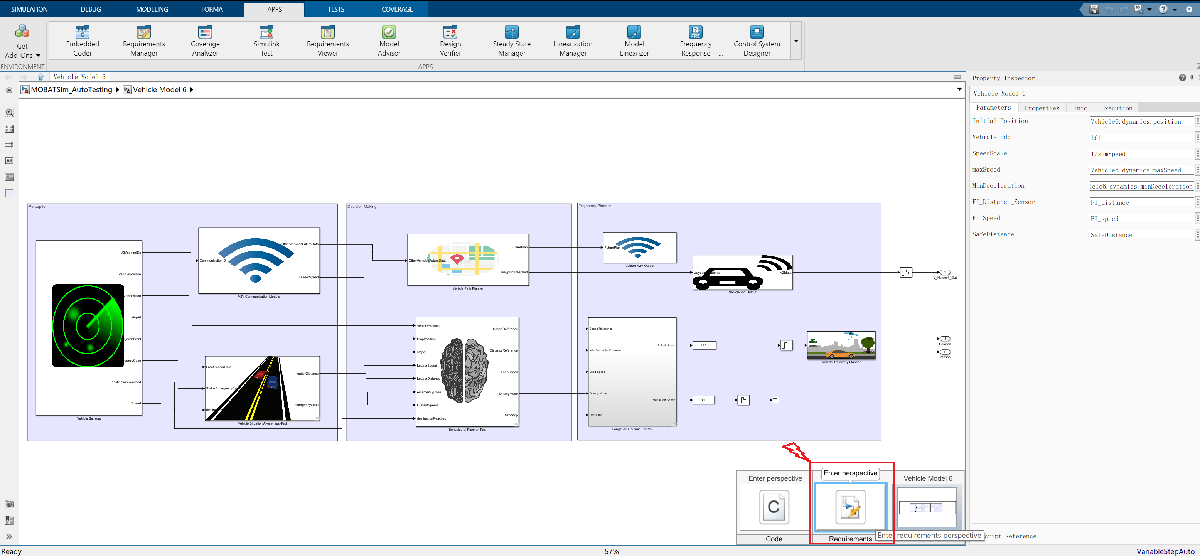

Then a new interface **Requirements Browser** will appear below the simulink model interface.

The process of creating a new requirement set and a new requirement in the **Requirements Browser** is consistent with the steps in the **Requirements Editor**.

- Click on the newly created requirement, you can author your requirements by writing the content, ID, summary etc. in the **Properities** tab in the **Property Inspector** pane on the right:

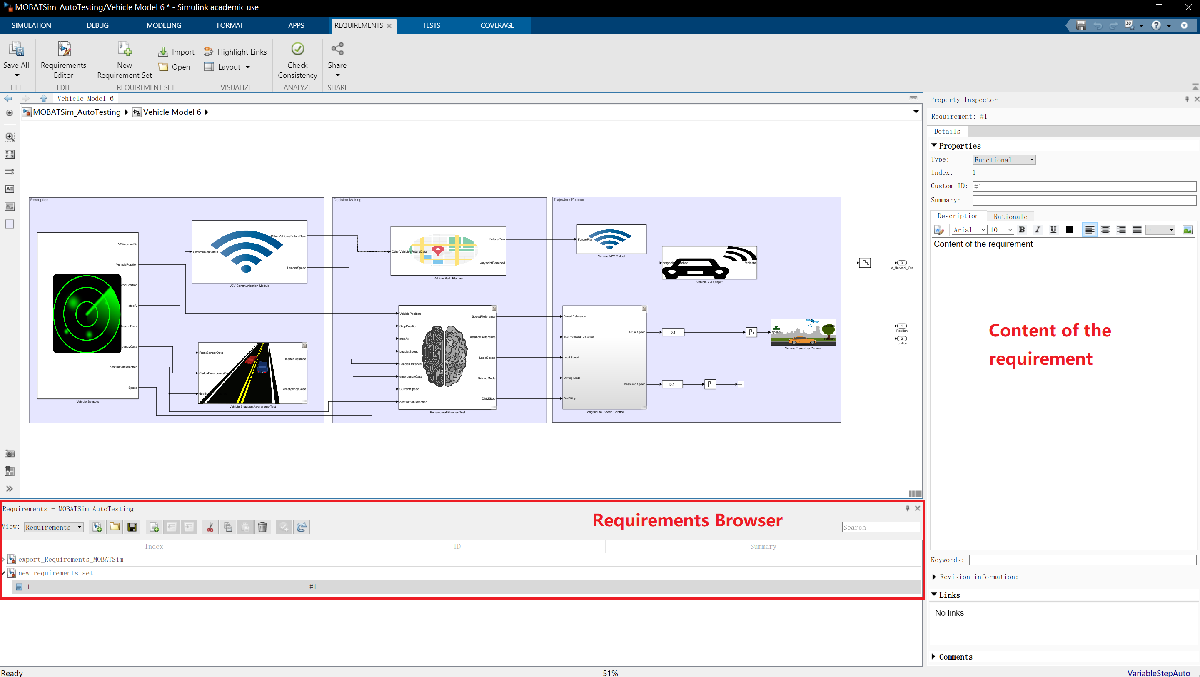

To go back to Table of Contents

## **C. Link Requirements to Blocks**

Because requirements themselves are something that cannot be understood by the machine, it is necessary to link requirements to different places to verify whether the tested blocks satisfy their corresponding requirements. 

After the requirements are created, the requirements should be linked with their corresponding block, the linked block need to satisfy these requirements. The connection is bidirectional, meaning that you can locate a requirement from a model element and a model element from a requirement.

Because you can manage your requirements through the Requirements Editor or Requirements Browser, there are also two ways to link the tested blocks with their corresponding requirements.

To go back to Table of Contents

### **1. Create Links through the Requirements Editor**

Because the connection between requirements and blocks is bidirectional, you can select the block to be linked in the Simulink model interface. 

- Right click on the requirements to be linked in the **Requirements Editor**, and click "**Link from "block_name"** " to create the links:

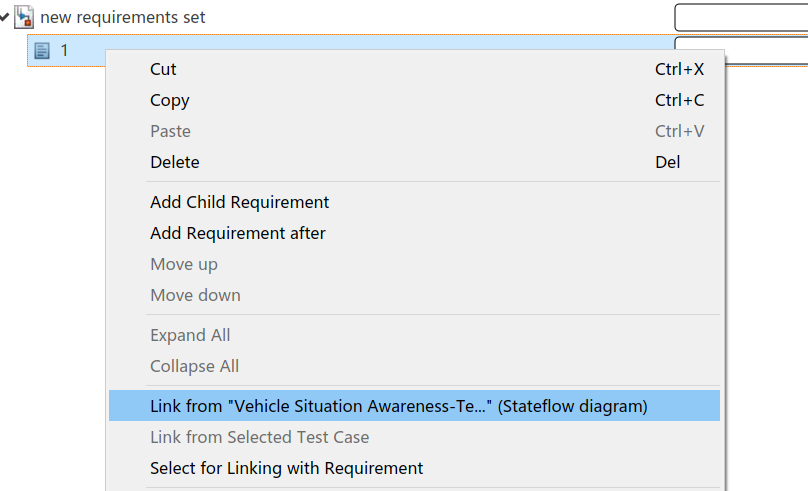

You can also first select the requirements to be linked in the **Requirements Editor**. 

- Right click on the block to be linked in the model interface, select "**Requirements**", and then click "**Link to Selection in Requirements Browser**" to create the links:

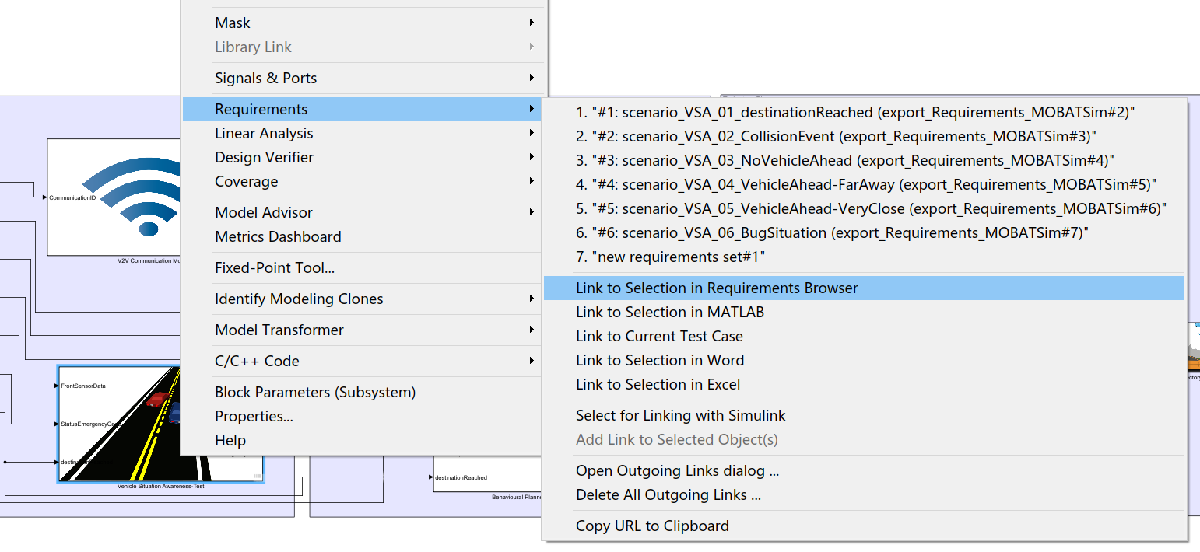

In addition to creating links by selecting blocks and requirements, you can also create links between requirements and blocks in a more direct way.

- Drag the selected requirements from the **Requirements Editor** or** Requirements Browser** and drop it on the corresponding block. 

To go back to Table of Contents

### **2. Create Links through the Requirements Browser**

The process of creating links through the Requirements Browser is the same as the process of creating links through the Requirements Editor.

To go back to Table of Contents

### 3. View Links between Requirements and Blocks

After creating the links, you can view these links through the linked blocks, Requirements Editor, or Requirements Browser.

After you create links between **requirements** and **blocks**, a traceability data file will be automatically generated, named "`TestModel_name.slmx`", and saved in the same path as the test model.

**Warning**: Files with the suffix "`.slmx`" are traceability data files. There are different traceability data files in the current folder. The automatically generated file "`TestModel_name.slmx`" corresponds to the existing file "`MOBATSim_AutoTesting.slmx`", which stores the link information between requirements and blocks. In a later step, when View Links between Test Cases and Requirements, there is another file with the suffix ".slmx" that stores the link between the requirements and the test cases.

To go back to Table of Contents

#### View Links through the linked Blocks

When you right click on a block and select "Requirements", all the requirements linked to the block will be displayed at the top of the menu that appears.

To go back to Table of Contents

#### View Links through the Requirements Editor

In the Requirements Editor, you can view the "**Implementation Status**" of each requirement. When the requirement has been linked to a block, the "**Implementation Status**" is displayed in blue. 

- Select a requirement, the corresponding linked block will be displayed on the **Links** tab on the right, click on the link can jump directly to the block in the Simulink model:

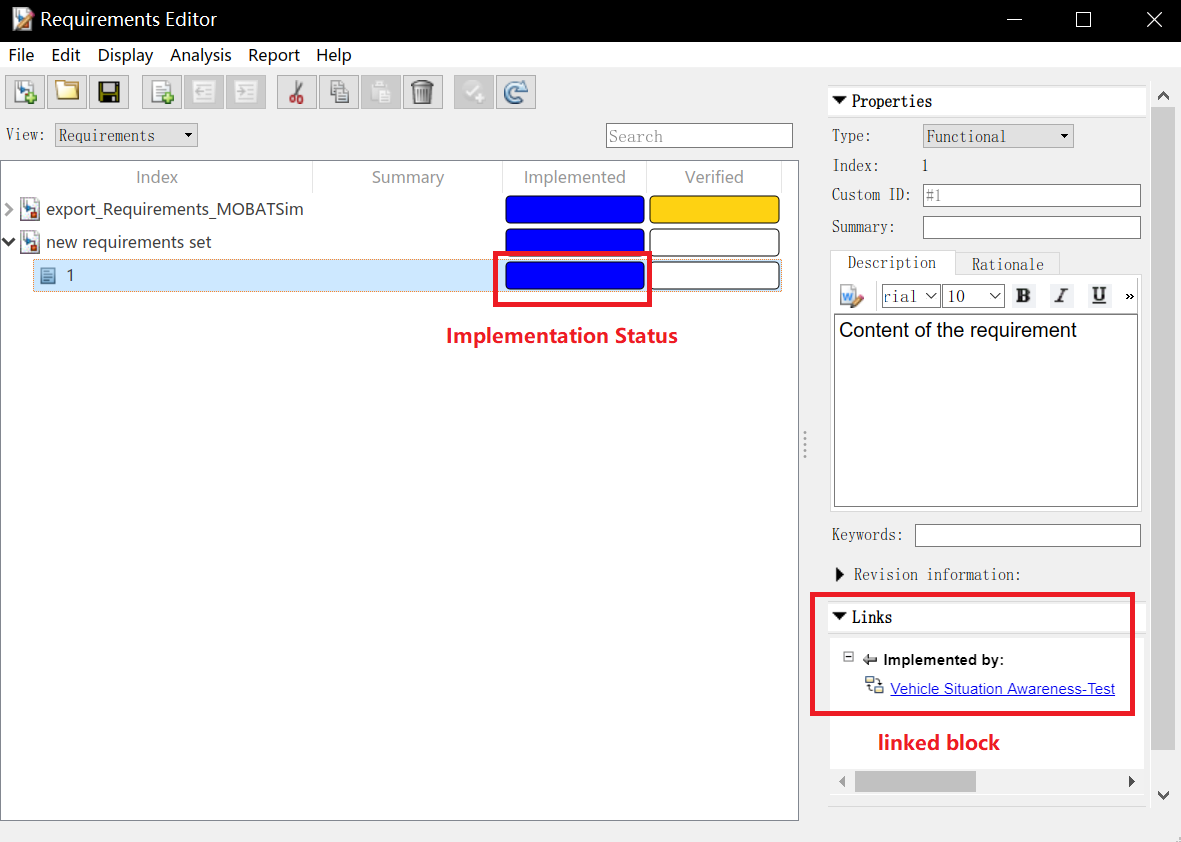

To go back to Table of Contents

#### View Links through the Requirements Browser

After you create the links, every time you enter the **Requirements Perspective** and open the **Requirements Browser**, a small badge will be displayed in the upper right corner of the blocks in the Simulink model which are linked with requirements. 

- Clicking on the badge will display all the requirements linked to this block:

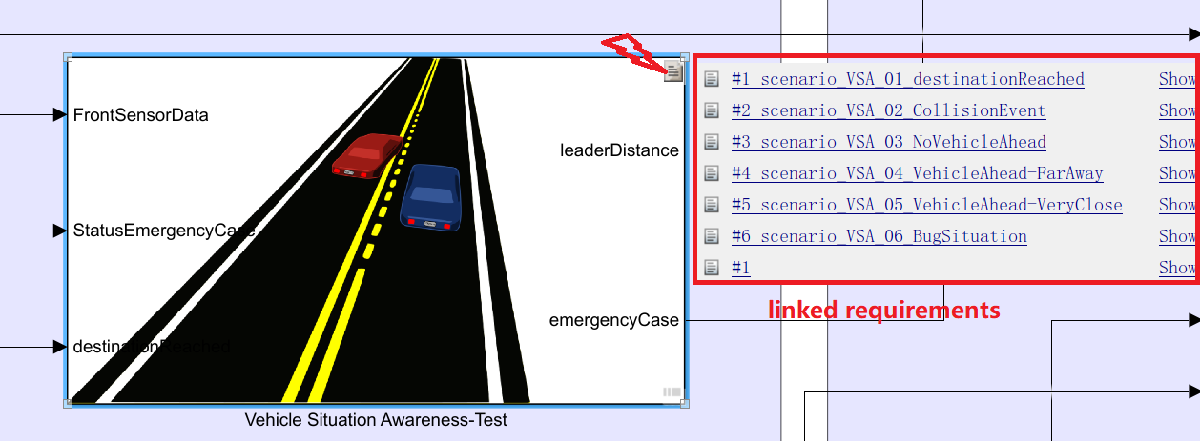

Select a requirement in the **Requiremens Browser**, the corresponding linked block will be displayed on the **Links** tab on the right, click to jump directly to the block in Simulink model(same as in **Requirements Editor**).

To go back to Table of Contents

# **III. Determine Test Signals**

Now you have defined the requirements of the blocks that need to be tested. To test these blocks, you need to check whether the existing input/output signals of the tested blocks are sufficient for testing and verifying all requirements. 

To go back to Table of Contents

## **A. Missing Signals**

If the existing input/output signals of a block are not sufficient for testing and verifying all requirements, you need to add input/output signals for the block. In MOBATSim, the blocks with missing signals are usually **MATLAB system** blocks, and these blocks usually hide a lot of signals. For the MATLAB system blocks to be tested, the missing input signal can be derived from the previous block.

In our example, we made some modifications to a MATLAB System block "**Vehicle Sensors**" in the model, and derived some internal signals from this block as the test input signals of the following blocks under test:

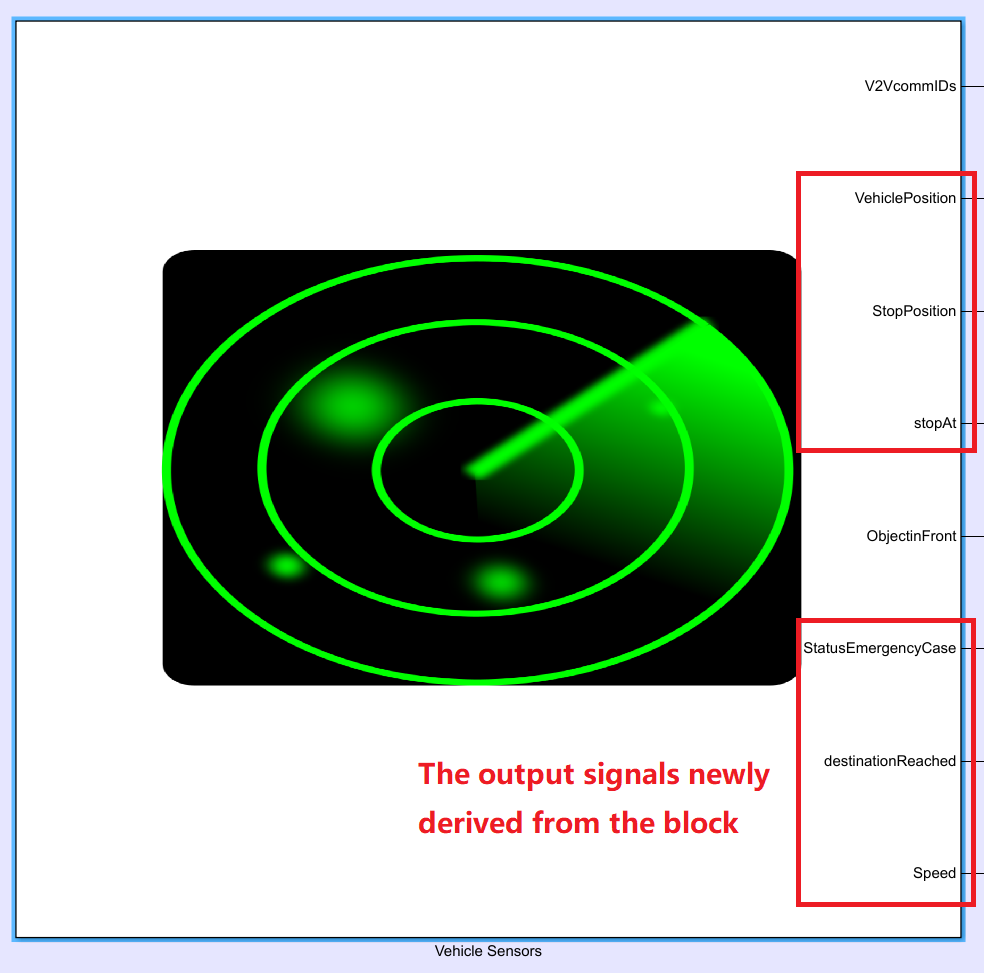

The file "`VehicleSensors_Test.m`" in the current folder is the encapsulated MATLAB code of the block "**Vehicle Sensors**" after modification.

To go back to Table of Contents

## **B. Enough signals**

If the existing signals are sufficient for testing, there is no need to modify the signals of the tested block.

To go back to Table of Contents

# **IV. Create Test Harness**

A test harness is a model that isolates the components under test, with inputs, outputs, and verification blocks configured for testing scenarios. You can create a test harness for a model component or for a full model. A test harness gives you a separate testing environment for a model or a model component. Here, you can isolate individual blocks for unit testing.

Compared to using separate models for unit testing, test harnesses offer management and synchronization capabilities in the model canvas.

For more detailed information about Test Harness, please click [here](https://www.mathworks.com/help/sltest/test-harnesses.html).

To go back to Table of Contents

## A. Start creating Test Harness

Right click on the block that needs to be tested, choose "**Test Harness**", and then click "**Create for 'block_name'** "  to open the Create Test Harness dialog box:

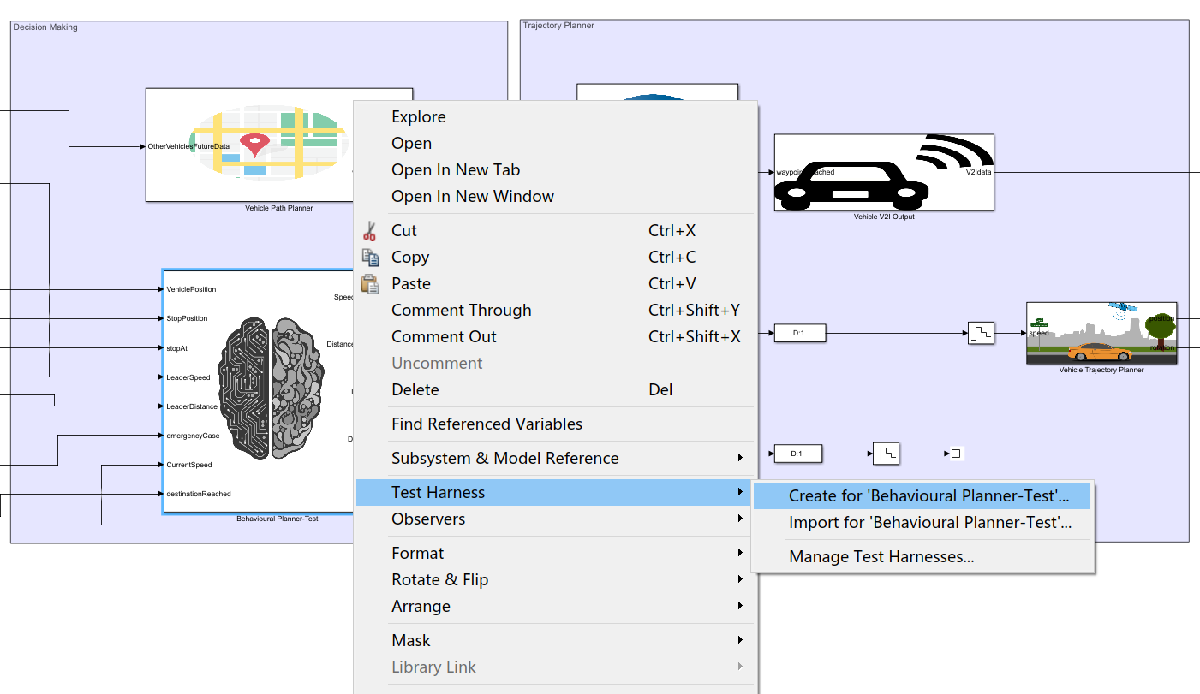

To go back to Table of Contents

## B. Specify the Properties of a Test Harness

In the Create Test Harness dialog box, you can specify different properties of the test harness. 

You can specify the name of the test harness, the Source and Sinks of the test harness, whether to create a separate test assessment block in the test harness model, etc. :

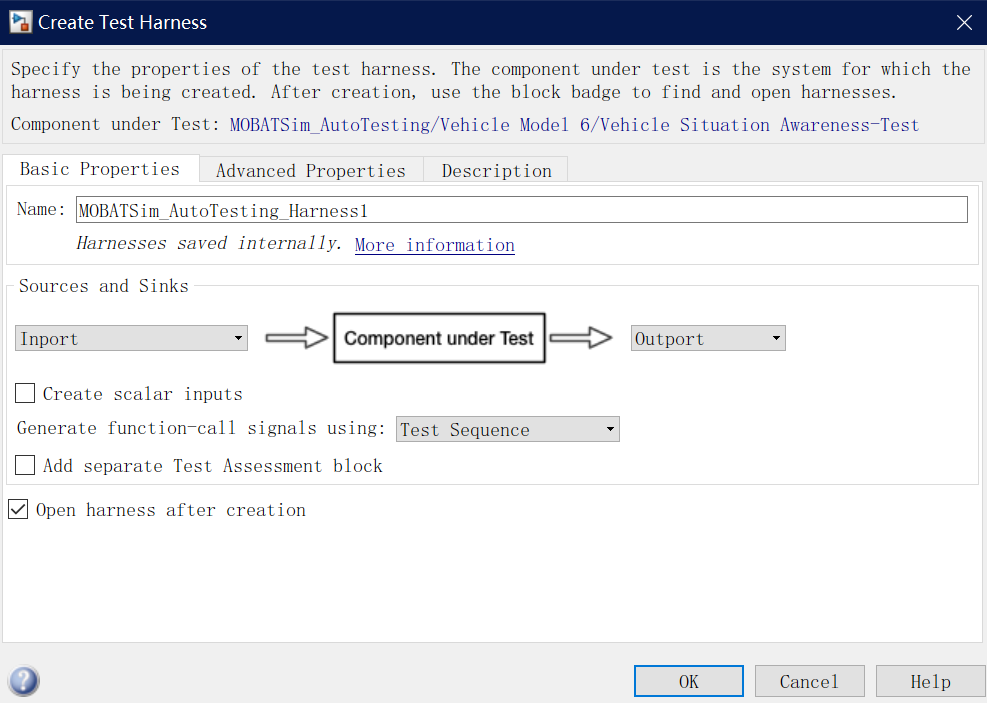

After setting the properties of the test harness, click **OK** to create a new test harness.

You can also create a new test harness directly through the following code:

sltest.harness.create('MOBATSim_AutoTesting/Vehicle Model 6/Vehicle Situation Awareness-Test', ... %specify the harness owner
    'Name','harness_name', ...        %set the name of test harness
    'Source','Signal Builder', ...    %choose Source
    'Sink','Outport', ...             %choose Sink
    'SeparateAssessment',true)        %add a seperate test assessment block

For more detailed information about properties of a test harness, please click [here](https://www.mathworks.com/help/sltest/ug/select-test-harness-properties-for-your-task.html).

To go back to Table of Contents

### 1. Sources and Sinks

**Sources** provide test inputs for the component under test in the test harness model, and **Sinks** specify the output of the test harness:

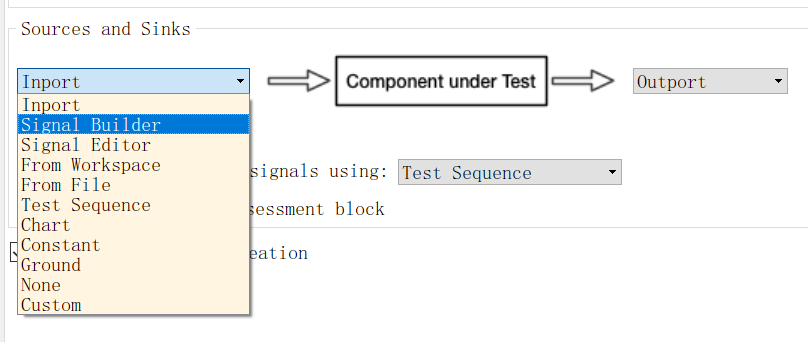

When selecting **Source**, if you use external data files as test inputs, choose "**From File**"; if you select the data in Workspace as test inputs, choose "**From Workspace**"; if you directly create test inputs for the component under test in the test harness model, you can choose these signal input blocks: Signal Builder, Signal Editor, Test Sequence.

In the existing test harnesses in this test model, we have chosen Signal Builder as test input generator.

When there is no need to export the test output data of the test harness, keep the default Sink unchanged, which is "Outport".

To go back to Table of Contents

#### Signal Builder

The Signal Builder block allows you to create interchangeable groups of piecewise linear signal sources and use them in a model. You can quickly switch the signal groups into and out of a model to facilitate testing.

- Double-click on the block to open the editor, and all input signals are displayed in the form of charts:

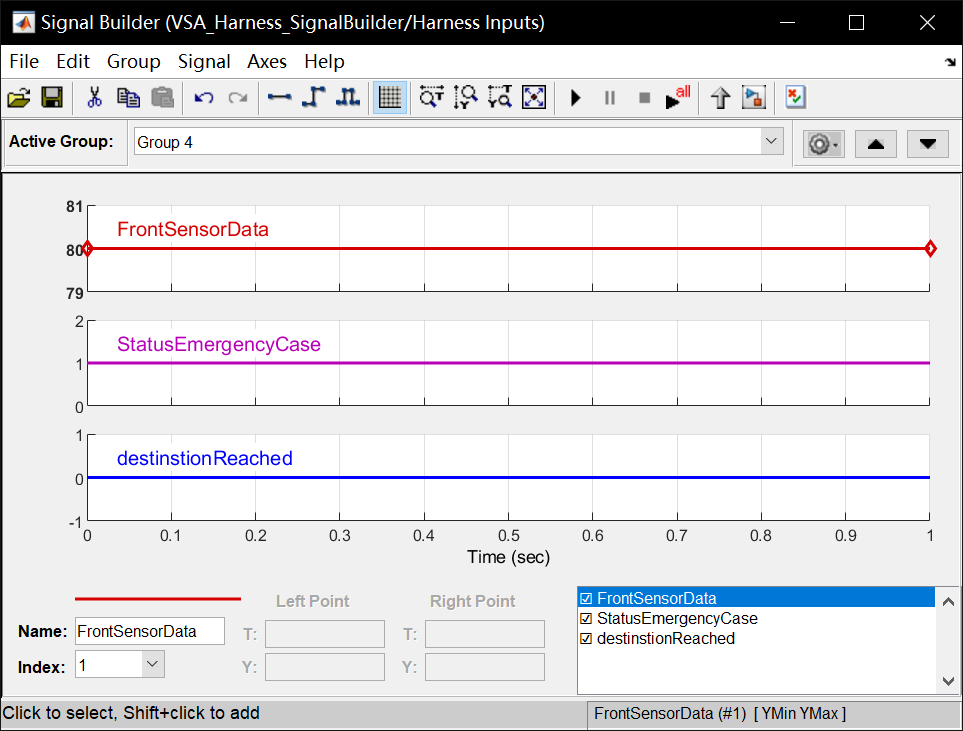

For more detailed information about Signal Builder, please click [here](https://www.mathworks.com/help/simulink/slref/signalbuilder.html).

To go back to Table of Contents

#### Signal Editor

The Signal Editor block displays, creates, and edits interchangeable scenarios. You can also use the block to switch scenarios in and out of models. 

The Signal Editor provides similar functionality to the Signal Builder block, but with greater flexibility. 

You can replace the Signal Builder with the Signal Editor block. To port signal data and properties from the Signal Builder block to Signal Editor block, use the [signalBuilderToSignalEditor](https://www.mathworks.com/help/simulink/slref/signalbuildertosignaleditor.html#mw_a9622ecc-d5ae-4842-9b47-960ba6006b8a) function.

For more detailed information about Signal Editor, please click [here](https://www.mathworks.com/help/simulink/slref/signaleditorblock.html).

To go back to Table of Contents

#### Test Sequence

The Test Sequence block can be used to create simulation testing scenarios, function calls, and assessments. In this block, you can define a test sequence using a tabular series of steps.

A test sequence consists of test steps arranged in a hierarchy. You can use a test sequence to define test inputs and to define how a test will progress in response to the simulation. A test step contains actions that execute at the beginning of the step. A test step can contain transitions that define when the step stops executing, and which test step executes next:

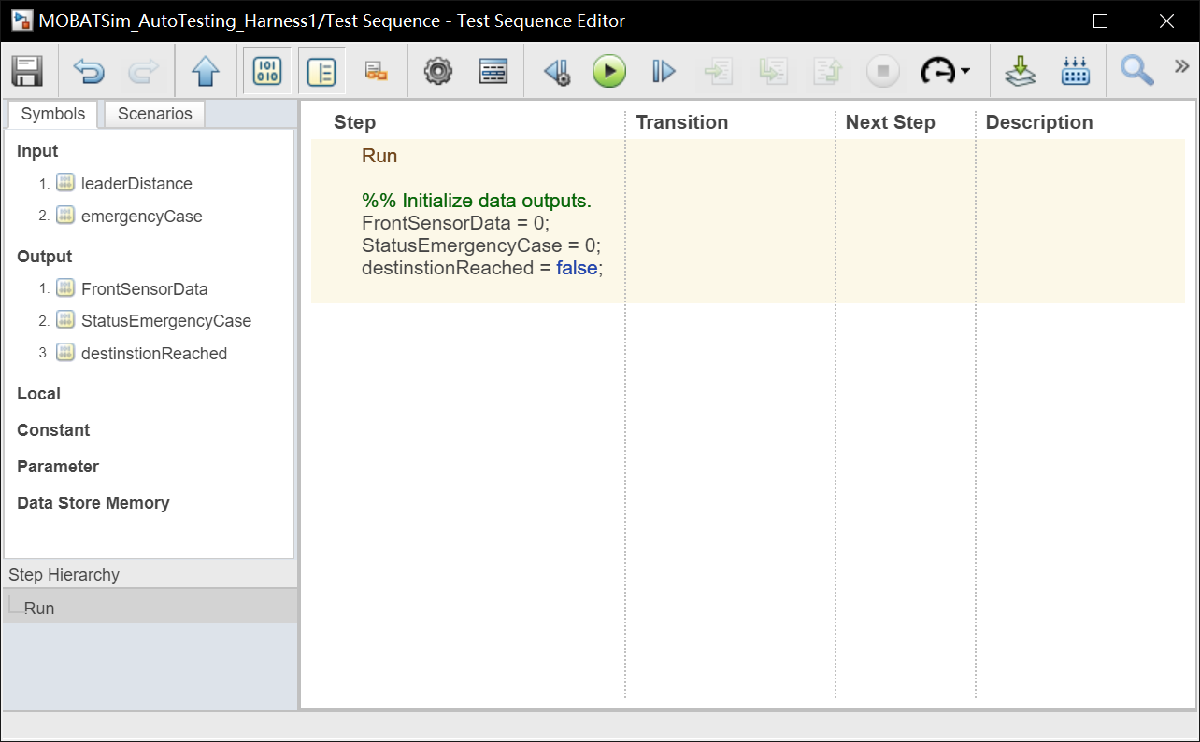

For more detailed information about Test Sequence, please click [here](https://www.mathworks.com/help/sltest/ug/introduction-to-test-sequences.html).

To go back to Table of Contents

### 2. Add seperate Test Assessment Block

In the Create Test Harness dialog box, you can select **Add separate Test Assessment block** to include a separate **Test Assessment block** in the test harness:

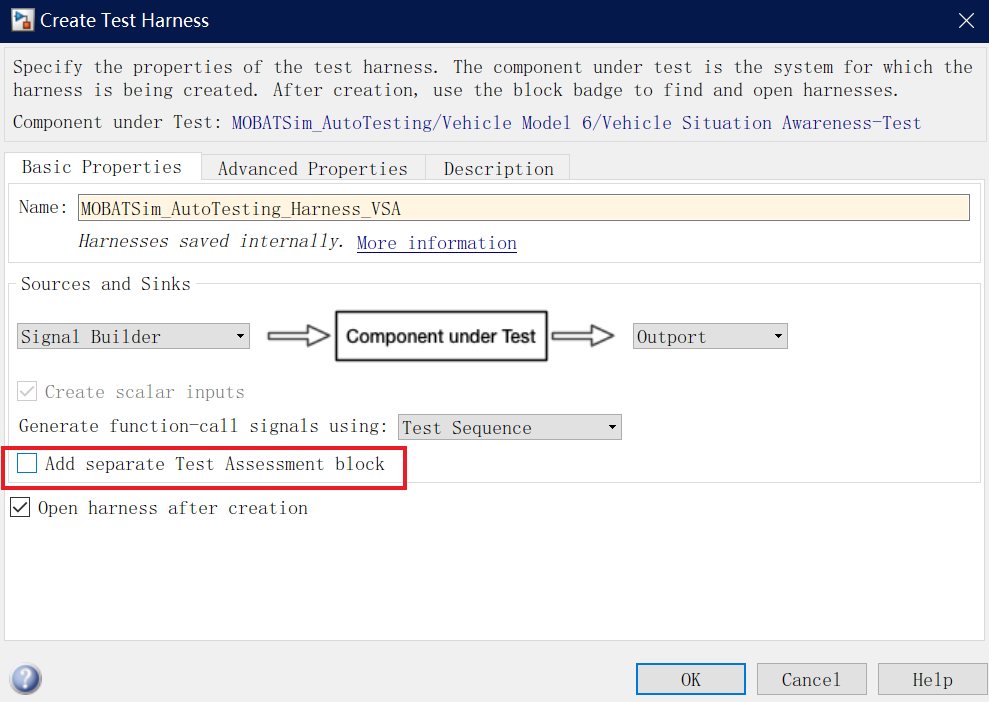

A **Test Assessment block** is a separate Test Sequence block configured with properties commonly used for verifying the component under test. In this block, use input and output signals to write logical or temporal requirements-based assessment criteria to verify whether the component under test meets the corresponding requirements in the test:

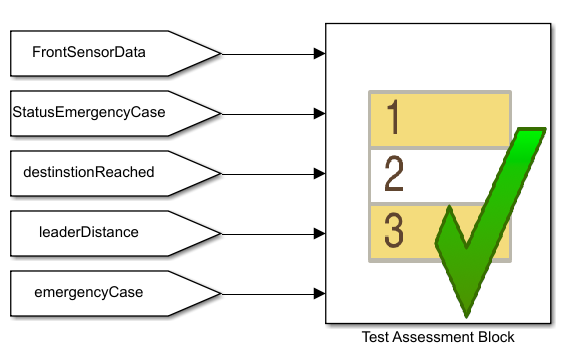

Double-click the **Test Assessment block** to open the Test Sequence Editor. By default, the **Test Assessment block** contains a test step Run, configured as a **When decomposition** sequence. 

- To change the transition type to a standard transition, right-click the top-level step and clear **When decomposition**:

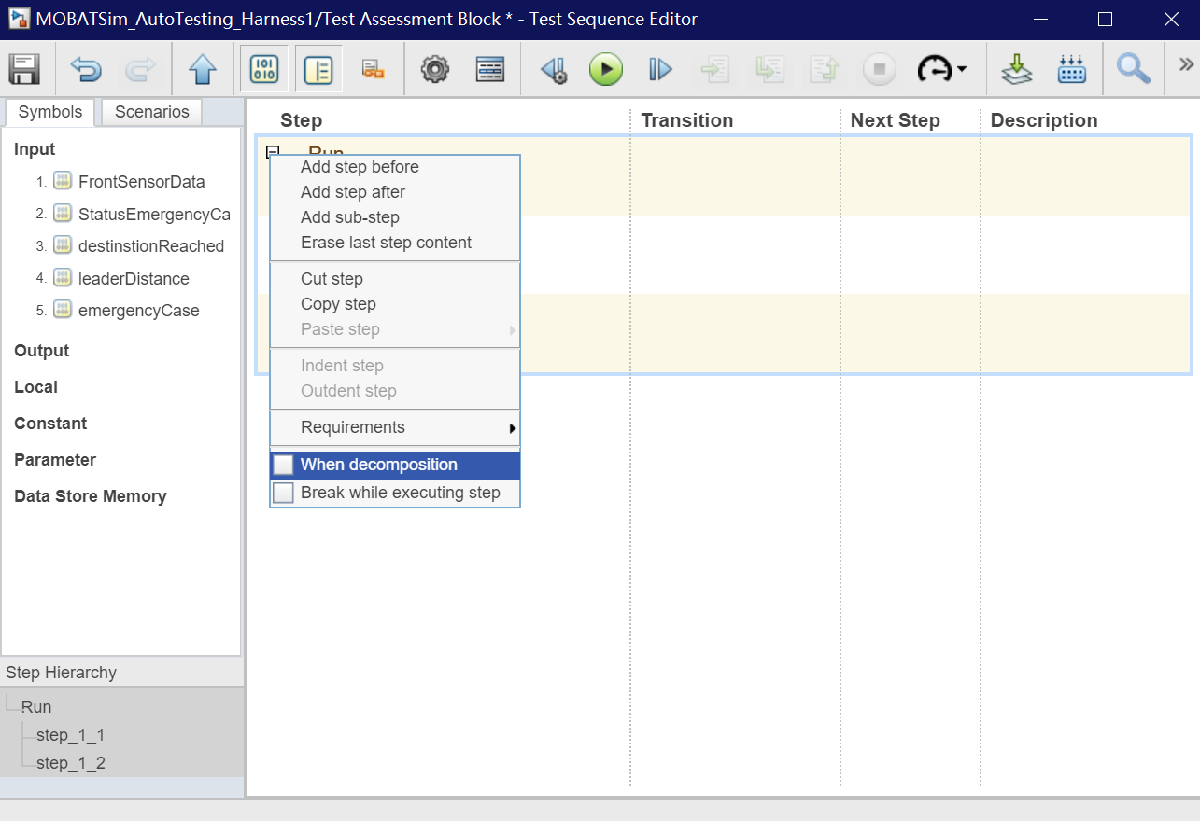

Generally we use two syntaxes to write test assessments: verify Statements and assert Statements**.**

In the existing test harnesses, we all use `verify` Statements to write test assessments that [verify multiple conditions at a time](https://ww2.mathworks.cn/help/sltest/ug/verify-multiple-conditions-at-a-time.html).

For more detailed information about Test Sequence and Assessment Syntax, please click [here](https://www.mathworks.com/help/sltest/ug/syntax-for-test-sequences-and-assessments.html).

To go back to Table of Contents

#### `Verify` Statements

A `verify` statement evaluates a logical expression and returns a pass, fail, or untested result for each simulation time step. `verify` statements can include temporal and conditional syntax. A failure does not stop simulation. 

A `fail` at any time step results in an overall `fail`. If there are no failing results, a `pass` at any time step results in an overall `pass`. Otherwise, the overall result is `untested`. Results appear in the **Verify Statements** section of the test results in the Test Manager.

For more detailed information about verfiy Statements, please click [here](https://ww2.mathworks.cn/help/sltest/ug/connecting-blocks-for-verify-statements.html).

To go back to Table of Contents

#### `Assert` Statements

You can use `assert` statements in a Test Assessment or Test Sequence block to stop executing an invalid test. 

`assert` evaluates a logical argument, but unlike `verify`, `assert` stops simulation. Failures stop simulation and returns simulation errors. To make results easier to interpret, add an optional message to display the simulation error message.

For more detailed information about assert Statements, please click [here](https://www.mathworks.com/help/matlab/ref/assert.html).

To go back to Table of Contents

## **C. Test Harness Model**

The created test harness models are divided into two types: the harness model with Test Assessment Block and the harness model without Test Assessment Block.

To go back to Table of Contents

### **1. Model with Test Assessment Block**

If you select Add separate Test Assessment block before, in this case, the test harness model includes a seperate Test Assessment block, a signal input block(Source), the isolated component under test, a signal output block(Sink):

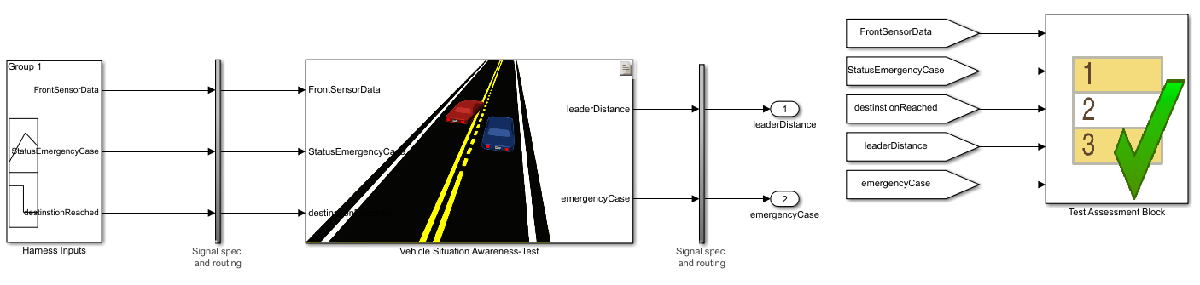

- Create test inputs for the test in the signal input block on the left in the harness model. 

The commonly used input blocks are Signal Builder, Signal Editor, Test Sequence.

-  Write logical or temporal test assessments in the **Test Assessment Block**.

The assessment criteria that are used to evaluate whether the component under test meets all requirements are written in this T**est Assessment Block**, that is, requirements-based assessments are integrated into In the test harness model. 

- After setting the test inputs and test assessments, close the test harness.

To go back to Table of Contents

### **2. Model without Test Assessment Block**

In this case, the test harness model includes a signal input block(Source), the isolated component under test, a signal output block(Sink):

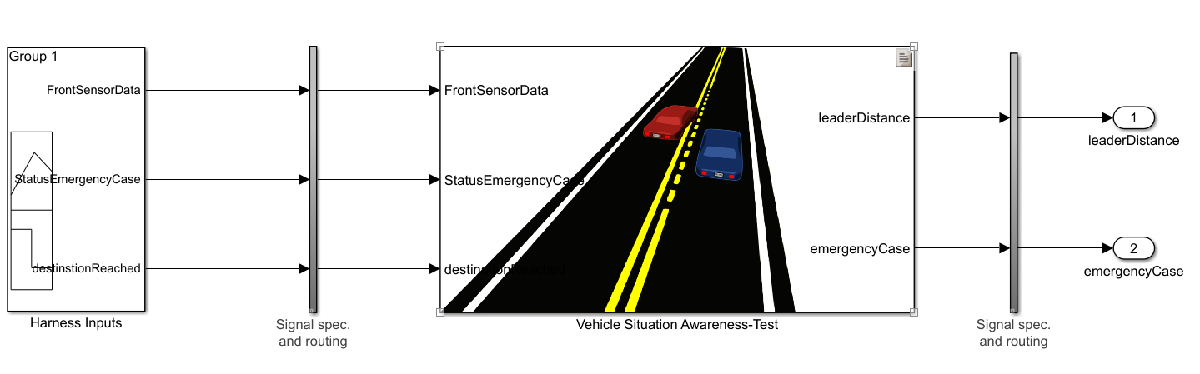

- Create test inputs for the test in the signal input block on the left in the harness model. 

Since the test harness model does not include a seperate **Test Assessment block**, test assessments cannot be written here. 

**Warning**: In this case, we will define test assessments in Test Manager later!

- After setting the test inputs, close the test harness.

To go back to Table of Contents

# **V. Create Test Cases**

Create a test file in the tool Simulink Test Manager, and create test cases for testing in the test file, then specify the properties of the test cases.

To go back to Table of Contents

## A. Simulink Test Manager

Using the Test Manager to run simulation tests allows you to manage numerous tests and to capture and manage results systematically.

To start the Test Manager, on the **Apps** tab, under** Model Verification, Validation, and Test**, click **Simulink Test**. On the **Tests** tab, click **Simulink Test Manager**.

You can also directly run the following code to open the Test Manager:

% Open Test Manager to view and edit test case
sltest.testmanager.view;

The Test Manager mainly consists of two parts: **Test Browser**, **Results and Artifacts**:

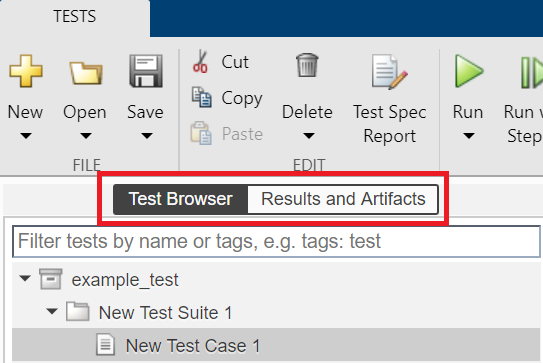

**Test Browser** is used to manage test files and test cases in the Test Manager, and set test options. 

**Results and Artifacts** are used to view and evaluate test results

To go back to Table of Contents

## B. Create Test Cases

Click **New** in the upper left corner of the Test Manager toolstrip, then choose **Test File **to create a new blank test file named with the suffix "`.mldatx`". When a new test file is created, a test suite and a test case will be automatically created in the test file by default. 

In our example, the existing test file is named "`UnitTest_MOBATSim.mldatx`".

There are different types of test cases. The test case created by default is a **baseline test case**. The baseline test case checks that the simulation results produce the same output as the baseline dataset, which determines the pass/fail criteria of the test case. To view an example of baseline test, please click [here](https://www.mathworks.com/help/sltest/ug/compare-model-output-to-baseline-data.html).

In our case, **simulation test case** is used for testing. 

- Right-click on the test case generated by default, choose "**Convert to**", and then click "**Simulation Test**":

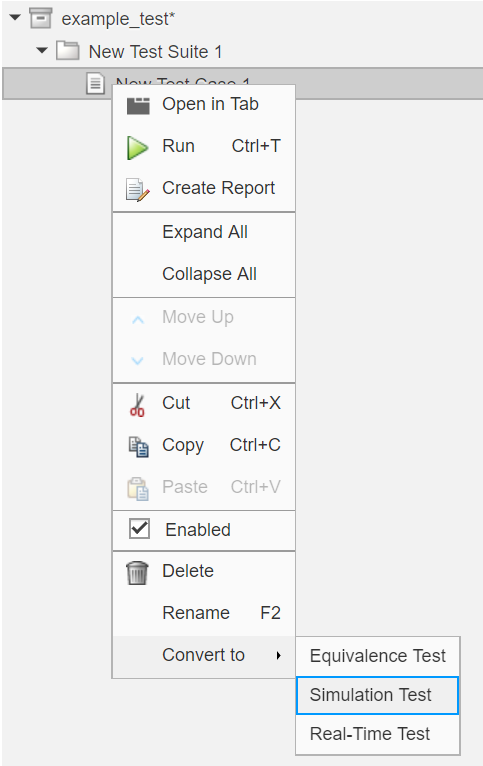

There are other types of test cases to choose from: **Equivalence Test** and **Real-Time Test**. 

The **equivalence test case** in the test manager compares signal output between two simulations to determine equivalence. **Equivalence test** is also known as **back-to-back test**. Equivalence test is usually used to compare the results of a model's normal simulation results with its software-in-the-loop, processor-in-the-loop, or hardware-in-the-loop simulation results. For more detailed information about Equivalence Test, please click [here](https://www.mathworks.com/help/sltest/ug/test-two-simulations-for-equivalence.html).

The **real-time test case **is used to execute an application on a standalone target computer that can connect to a physical system.

You can directly run the following code to create a new test file and generate a test suite and test cases from it:

% Create the test file, test suite, and test case structure

%create a new test file
tf = sltest.testmanager.TestFile('TestFile_name');

% Remove the default test suite
tsDel = getTestSuiteByName(tf,'New Test Suite 1');
remove(tsDel);

%create a new test suite
ts = createTestSuite(tf,'TestSuite_name');

%create a new test case with simulation mode
%'simulation/equivalence/baseline' specifies different type of the test case
tc = createTestCase(ts,'simulation','TestCase_name');   

% Open Test Manager to view and edit test case
sltest.testmanager.view;

You can also directly run the following code to call the test file that already exists in our example:

% Load the example test file
sltest.testmanager.load('UnitTest_MOBATSim')

% Open Test Manager to view and edit test cases
sltest.testmanager.view;

To go back to Table of Contents

## C. Specify the Properties of Test Cases

After you create the test cases, you need to make some settings for the test file and each test case.

First of all, you must know that the test file is at the top of the hierarchy. According to your settings, it will contain several test suites of different levels. The test suites at the lowest level contain several test cases. Then the settings for test suites are valid for all the test cases under it. The last is the test case's own settings.

When certain settings apply to all test cases, you should directly modify the corresponding properties in the test file.

The main settings we perform are: set the Coverage Settings for the test file; for each test case, set its Requirements, System under Test, Inputs, and when necessary, set its Logical and Temporal Assessments for some test cases.

To go back to Table of Contents

### 1. Coverage Settings

The settings here apply to all test cases, so modify the settings of the test file directly.

Click the test file, the properties of the test file will be displayed on the right side of the Test Browser. 

- Expand the tab "**COVERAGE SETTINGS**" to select the test coverage settings:

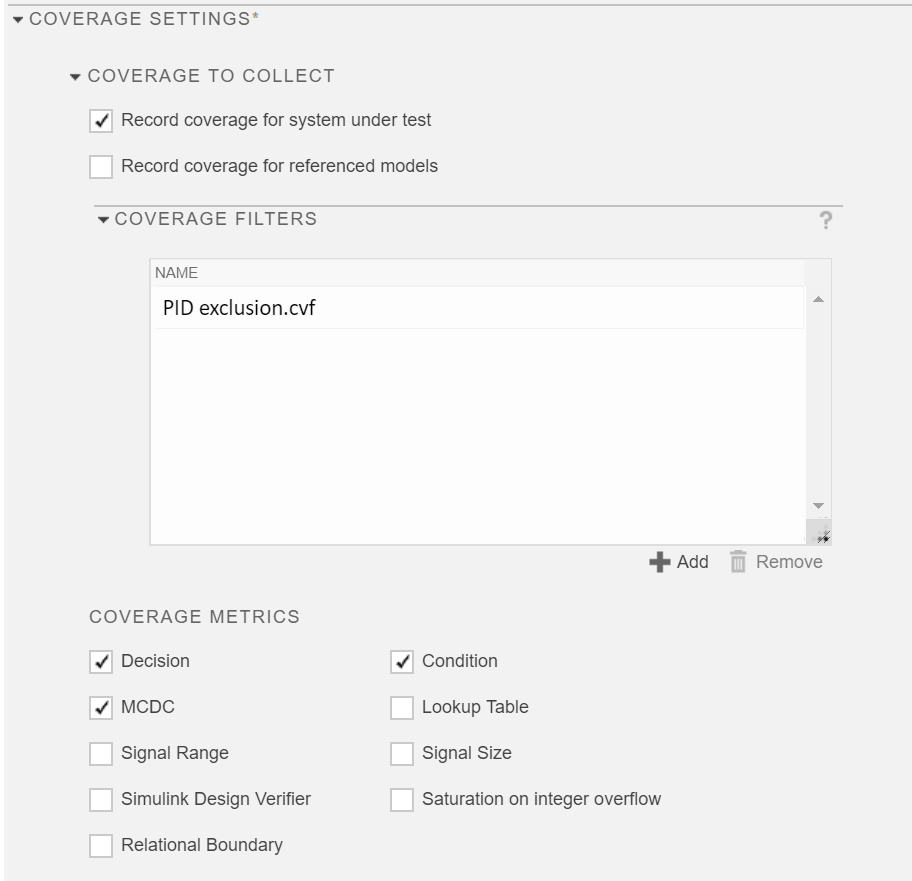

To go back to Table of Contents

#### Coverage to Collect

Check "**Record coverage for system under test**" under the tab **COVERAGE TO COLLECT**.

To go back to Table of Contents

#### Coverage Filters

A file with the suffix "`.cvf`" can be added under the tab **COVERAGE FILTERS** to exclude certain components from coverage analysis, and the coverage information of these components is not collected during the test. Because not all components can be analyzed by the selected coverage metrics.

Here, we need to exclude the component `PID controller` in the Simulink library from coverage analysis, so we created a file called "`PID exclusion.cvf`" and added it here:

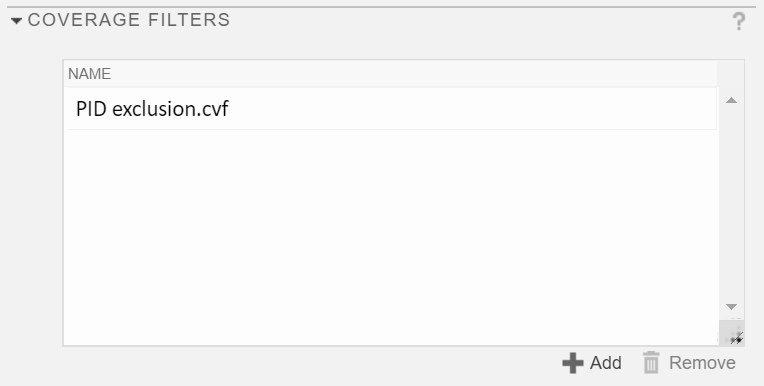

You can directly use the following code to add **coverage filter** to the test file in our example:

% Open Test Manager
sltest.testmanager.view;

% Load the example test file
testFile = sltest.testmanager.load('UnitTest_MOBATSim');

% Get coverage settings object from the test file
cov = getCoverageSettings(testFile);
cov.RecordCoverage = true;

% Specify a coverage filter
cov.CoverageFilterFilename = "PID exclusion.cvf";

In our example we have exluded PID from the coverage because not all types of blocks can be covered. For more detailed information about which components can receive which coverage, please click [here](https://www.mathworks.com/help/slcoverage/ug/model-objects-that-receive-coverage.html).

If you have other components that you do not want or cannot collect coverage information during the test, you need to [create and use Coverage Filters](https://www.mathworks.com/help/slcoverage/ug/creating-and-using-coverage-filters.html), to create the same file and add it here. 

To go back to Table of Contents

#### Coverage Metrics

Under the tab** COVERAGE METRICS**, you can select the type of coverage you want to collect in the test, and different coverage metrics analyze different coverage information. Usually we choose **Decision**(Decision Coverage), **Condition**(Condition Coverage), **MCDC**(Modified Condition/Decision Coverage):

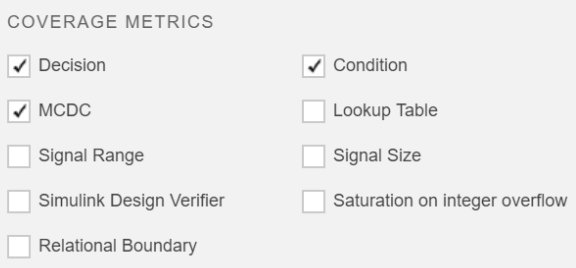

You can also use the following code to **specify coverage metrics** for our example test file: 

(If the previous code has been run, the annotated code below is not needed)

% Open Test Manager
%sltest.testmanager.view;

% Load the example test file
%testFile = sltest.testmanager.load('UnitTest_MOBATSim');

% Get coverage settings object from the test file
%cov = getCoverageSettings(testFile);
%cov.RecordCoverage = true;

% Enable Decison,Condition,MCDC coverage metrics
cov.MetricSettings = "dcm";

For more detailed information about Model Coverage, please click [here](https://www.mathworks.com/help/slcoverage/ug/types-of-model-coverage.html).

To go back to Table of Contents

### 2. Requirements

Click on a test case, expand the tab **Requirements** on the right side of the interface, here link the test case and the requirements verified by the test case.

The links between test cases and requirements here are the same as the previous links between blocks and requirements, which are bidirectional. 

- You can create a link by selecting the corresponding requirements in the Requirements Editor or Requirements Browser, and then clicking **Add** under the tab **Requirements** of the test case, and then clicking "**Link to Selected Requirement**":

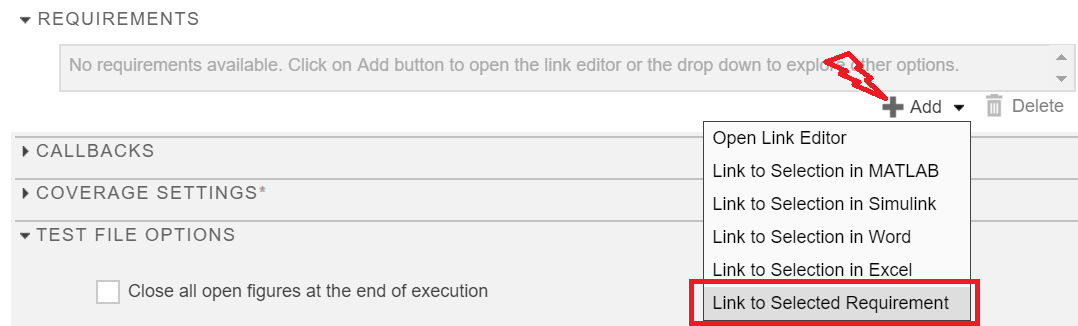

- You can also select the test case to be linked in the Test Manager first, then right-click the requirements to be linked in the **Requirements Editor** or **Requirements Browser**, and select "**Link from Selected Test Case**" to create a link:

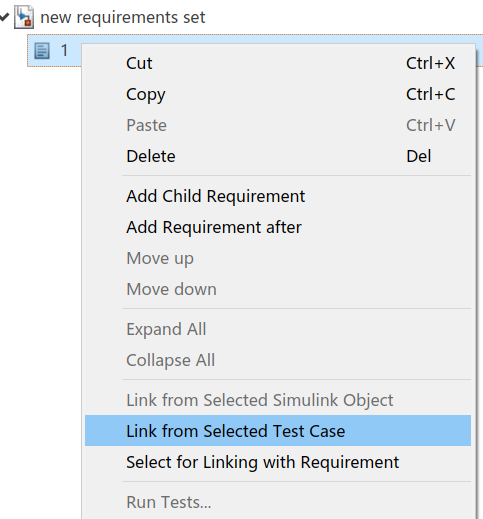

To go back to Table of Contents

### 3. System under Test

Expand the tab **SYSTEM UNDER TEST**, specify the model you want to test. 

- Click **Use current model **button to automatically choose the currently activated model for the test case.

- Then select the corresponding test harness under the tab **TEST HARNESS** to use for the test case.

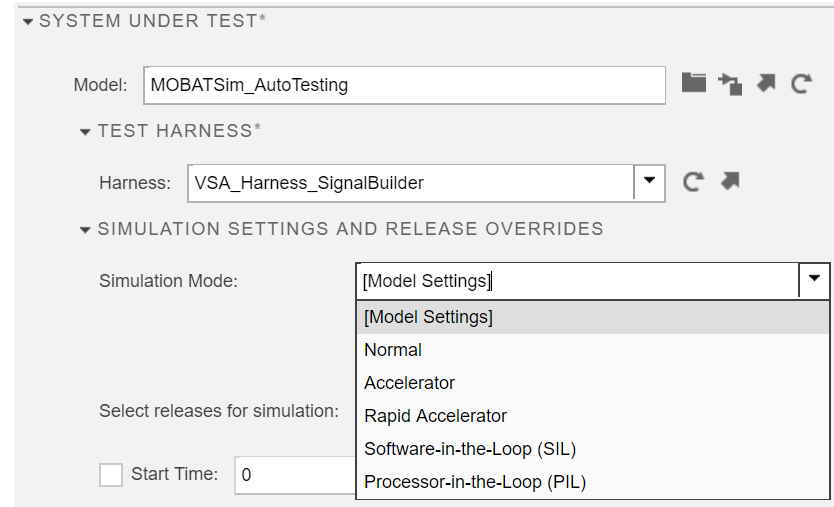

Under the tab **SIMULATION SETTINGS AND RELEASE OVERRIDES, **the default **Simulation Mode** is **[Model Setting]**, which is also known as** Normal** in the drop-down list:

**Normal** mode offers the greatest flexibility for making model adjustments and displaying results, but it runs the slowest.

**Accelerator** mode lies between Normal and Rapid Accelerator modes in performance and in interaction with your model. Accelerator mode does not support most runtime diagnostics.

**Rapid Accelerator** mode runs the fastest, but this mode does not support the debugger or profiler, and works only with those models for which C code or MEX file is available for all of the blocks in the model.

A **software-in-the-loop (SIL)** simulation compiles generated source code and executes the code as a separate process on your host computer. By comparing normal and SIL simulation results, you can test the numerical equivalence of your model and the generated code.

With **Processor-in-the-Loop(PIL)** simulation mode, you test the compiled object code that you intend to deploy in production by running the object code on real target hardware or an instruction set simulator.

You can use the following code template to specify the tested model and test harness for a specific test case:

% Load a tets file
tf = sltest.testmanager.load('TestFile_name');

% Get the test suite by test suite name
ts = getTestSuiteByName(tf,'TestSuite_name');

% Get the test case object by test case name
tc = getTestCaseByName(ts,'TestCase_name');

% Assign the system under test to the test case
setProperty(tc,'Model','TestModel_name');

% Assign the Test Harness to the test case
setProperty(tc,'HarnessName','TestHarness_name');

To go back to Table of Contents

### 4. Inputs

Here, you can choose whether to use external files as the test inputs of the test cases. If you use different signal groups in the signal input block of the test harness model to define different test scenarios, then you need to specify the signal group for testing for the test case:

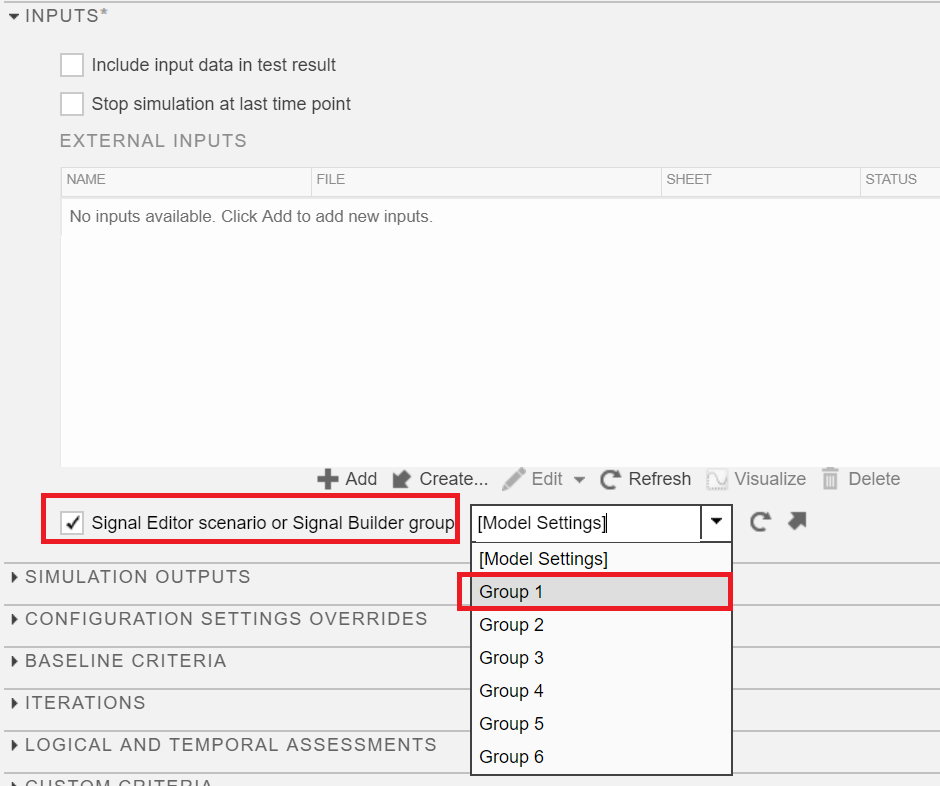

The choice here only appears - when the signal input block in the test harness model corresponding to the test case is **Signal Builder** or **Signal Editor**. Since we are using scenarios-based testing, in the** Signal Builder** block, we define different **signal groups**. Each **signal group** is a specific test input vector, which represents a specific **test scenario** we defined. When we specify this signal group for the test case, running and evaluating the test case is equivalent to testing and evaluating whether the behavior of the tested block satisfies the requirements in this test scenario.

For example, **Signal Group 1** in the above figure represents such a test scenario in our example: the vehicle has reached the destination; **Signal Group 2** in the above figure represents such a test scenario in our example: the vehicle has not reached the destination, and the vehicle has collided with other vehicles.

To go back to Table of Contents

### 5. Logical and Temporal Assessments

If you have previously added **Test Assessment blocks** to all test harness models, you can skip this step. You don't need to author assessments for test cases anymore.

If you **did not** select add seperate Test Assessment block for some test harness when you created the test harness model earlier, then you need to add assessments here for the test cases executed by those test harnesses that do not include a **Test Assessment block**.

For more detailed information about how to author the logical and temporal assessments here, please click [here](https://www.mathworks.com/help/sltest/ug/temporal-assessment-parameters.html).

To go back to Table of Contents

## D. View Links between Test Cases and Requirements

Just like the previous View Links between Requirements and Blocks, you can view these links through the linked test cases, Requirements Editor, Requirements Browser.

After you create links between **test cases** and **requirements**, a traceability data file will be automatically generated, named "`TestFile_name.slmx`", and saved in the same path as the test file. 

**Warning**: The file "`TestFile_name.slmx`" generated here corresponds to the existing file "`UnitTest_MOBATSim.slmx`", which is used to store the link information between test cases and requirements. Pay attention to the distinction between the file generated here and the file that stores the link information between requirements and blcoks mentioned in the previous step View Links between Requirements and Blocks!

To go back to Table of Contents

### 1. View Links through the linked Test Cases

After creating the link between the **test case** and the **requirement:**

- Click on the test case, you can see the linked requirement of the test case in the tab **Requirements**:

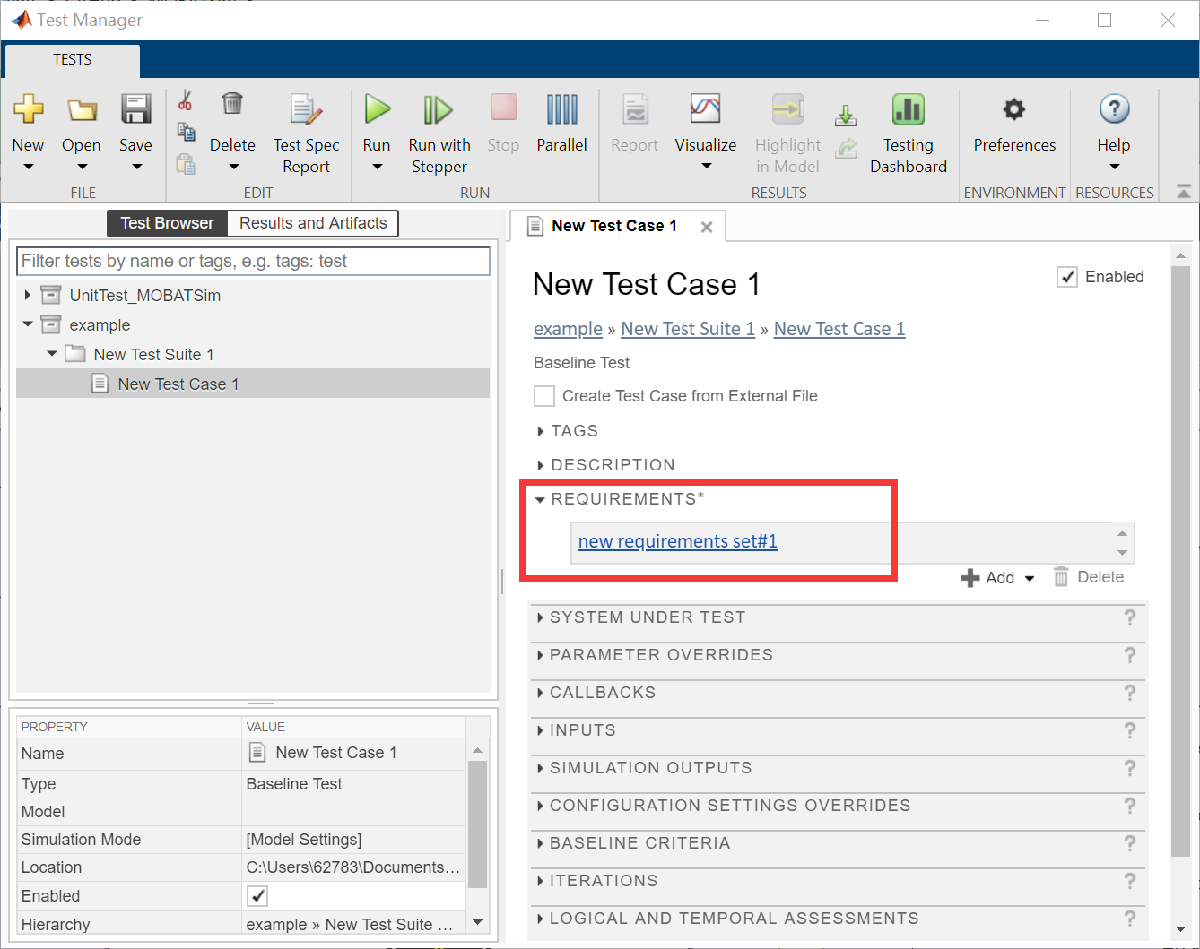

Click on the link can jump directly to the corresponding requirement in the **Requirements Editor**.

To go back to Table of Contents

### 2. View Links through the Requirements Editor

After creating the link between the test case and the requirement, click on the requirement, and you can see that its **Verification Status** is displayed in yellow, which means that the requirement is linked to at least one test case, but the linked test case has not been run. Under the tab **Links** on the right, the linked test case of the requirement will be displayed:

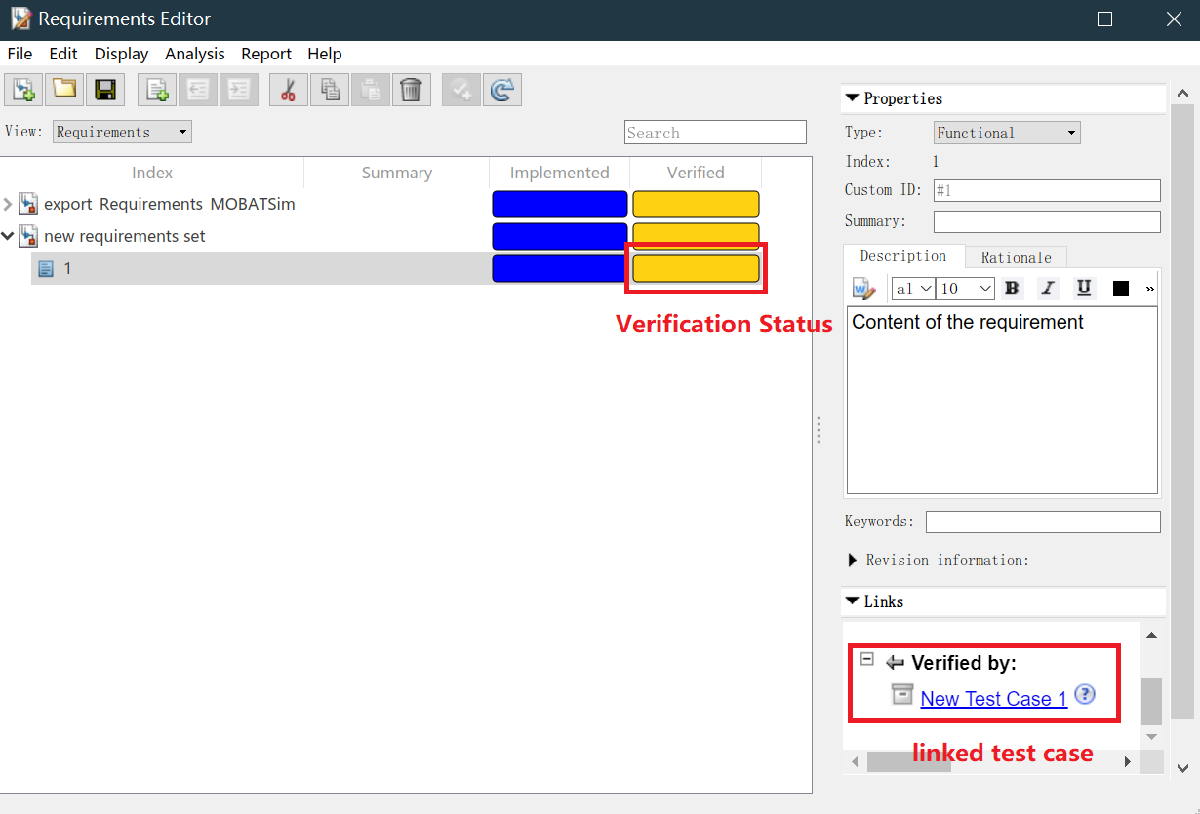

Click on the link can jump directly to the corresponding test case in the **Test Manager**.

To go back to Table of Contents

### 3. View Links through the Requirements Browser

In the **Requirements Browser**, you cannot view the Verification Status. Click the linked requirement, and the linked test case will be displayed under the tab** Links** on the right (the same as in the **Requirements Editor**).

To go back to Table of Contents

# **VI. Run Test Cases**

After you set the attributes of all test cases, you can run specified test cases, or test suites, or the entire test file to execute the test. After running these test cases, you can click **Results and Artifacts** to view the test results.

Select the specified test cases, or test suites, or the entire test file, and click **Run** in the toolstrip to run these test cases to execute the test.

To go back to Table of Contents

# **VII. View Test Results**

After a test case has finished running in the **Test Manager**, the test case result becomes available in the **Results and Artifacts** pane. Test results are organized in the same hierarchy as the test file, test suite, and test cases that were run from the **Test Browser** pane. In addition, the **Results and Artifacts** pane shows the criteria results and simulation output, if applicable to the test case.

To go back to Table of Contents

## A. Test Results Interface

Below we will introduce the test results after testing a certain block in our test model. When we open the test result on the left, click on the top level of the test result, and the following five parts information are displayed:

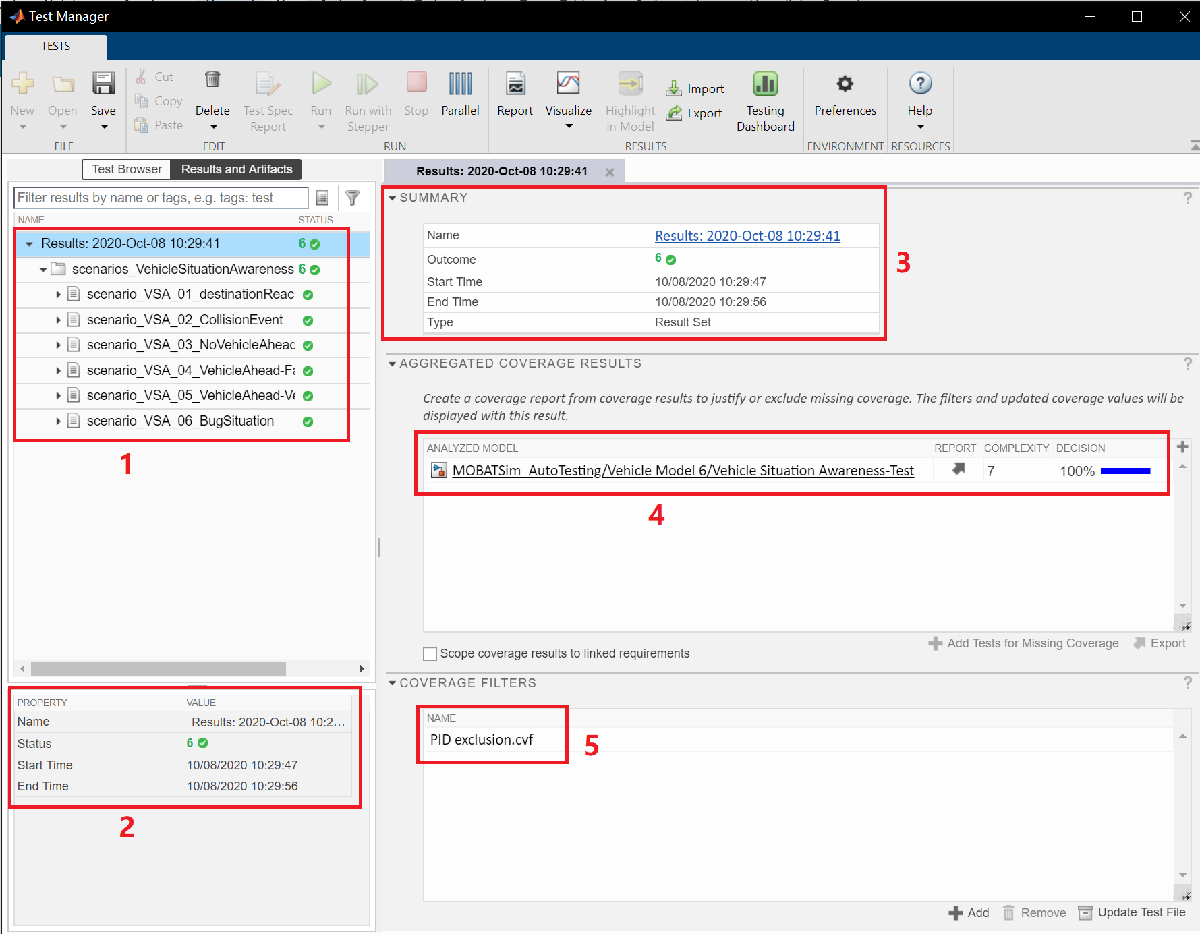

- Test results of the test suite and each test case, the green icon indicates that the test case passed the test;

- Information about the test, such as the test time, and the status of the test result;

- The summary information of the test, when at the top level of the test result, the content is the same as part 2;

- Test coverage result of the tested block in the selected coverage metrics;

- Coverage Filter information.

We have selected three coverages in Coverage Metrics, but only the results of **Decision Coverage** are shown here, because the tested block only contains parts that can be analyzed by **Decision Coveage**.

- Double-click a test case result,  and select **Expand All Under** to see all the detailed test results of this test case:

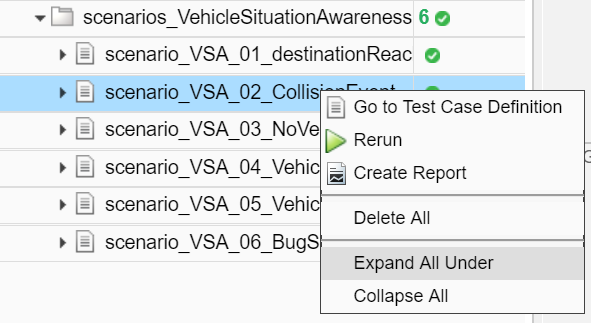

To go back to Table of Contents

### 1.** Verify Statements**

The detailed test results of this test case are divided into two parts:** Verify Statements** and **Sim Output**.

- Expand the test results of a test case, and then expand the section of** Verify Statements**, you can see the status of different assessments:

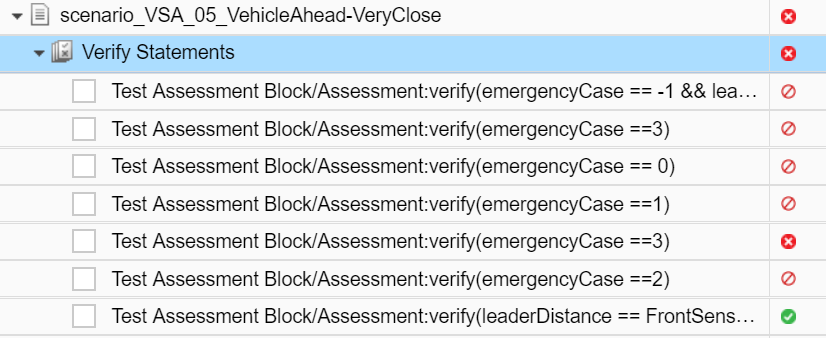

(In order to see all the types of test results, here we've changed the assessments criteria so that a test case intentionally fails the test!)

The green mark  indicates that the assessment was triggered when the test case was run, and the test case passed the assessment.

The prohibition mark   indicates that the assessment has not been triggered during the running of the test case.

The red mark  indicates that the assessment was triggered when the test case was run, but the test case failed the assessment.

**Warning**: The contents in the Test Assessment Block contain all assessments criteria of the tested model, that means, some assessments criteria may be triggered during the running of test case 1, and other assessments criteria may be triggered during the running of test case 2 or other test cases etc.. It is not necessary that one test case should be evaluated by all assessments. 

- Clicking to check the selection box in front of a `verify` assessment will open the **Visualize** pane on the right and display the details of the `verify` assessment in the test:

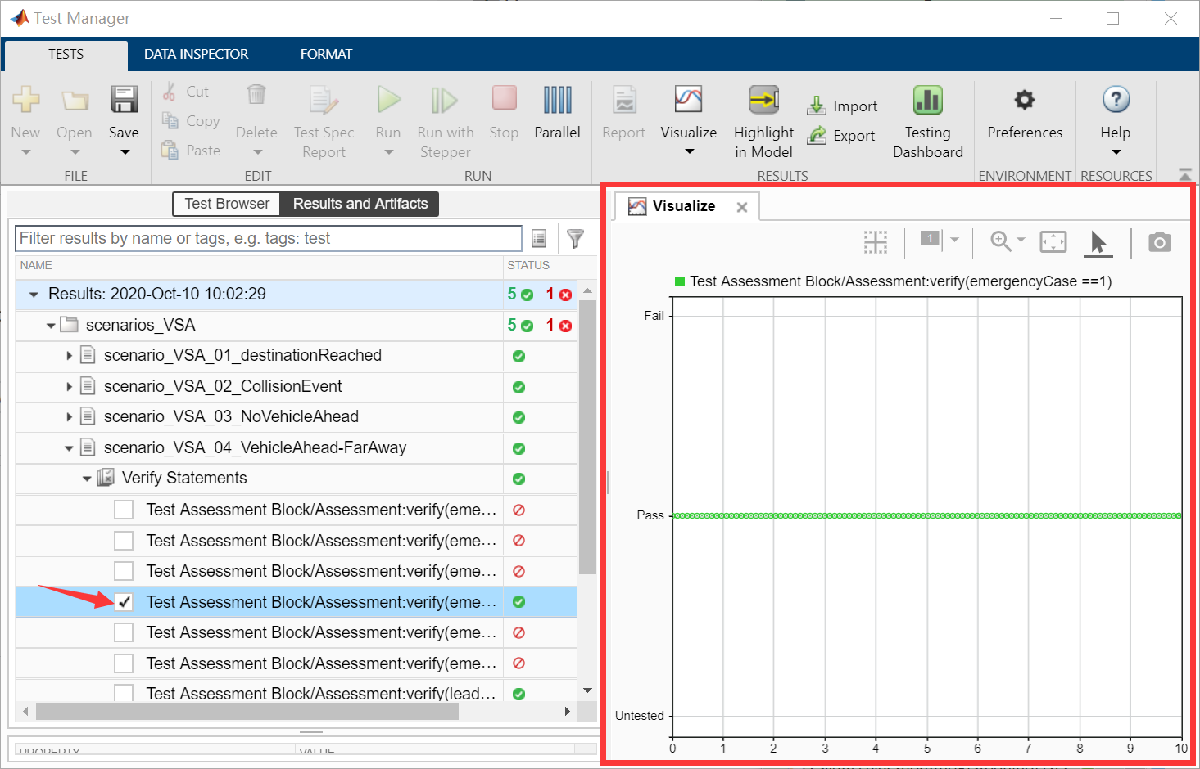

If the test case **passes** this assessment in the test, it will display:

If the test case **fails** this assessment in the test, it will display:  

If the test case **does not trigger** the assessment in the test, it will display:  

To go back to Table of Contents

### 2. **Sim Output**

Under the section of **Sim Output**. you can see the simulation outputs of the tested block under this test case after the test.  

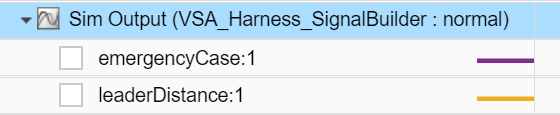

- Clicking to check the selection box in front of a signal name will open the **Visualize** pane on the right and display the details of that signal in the test:

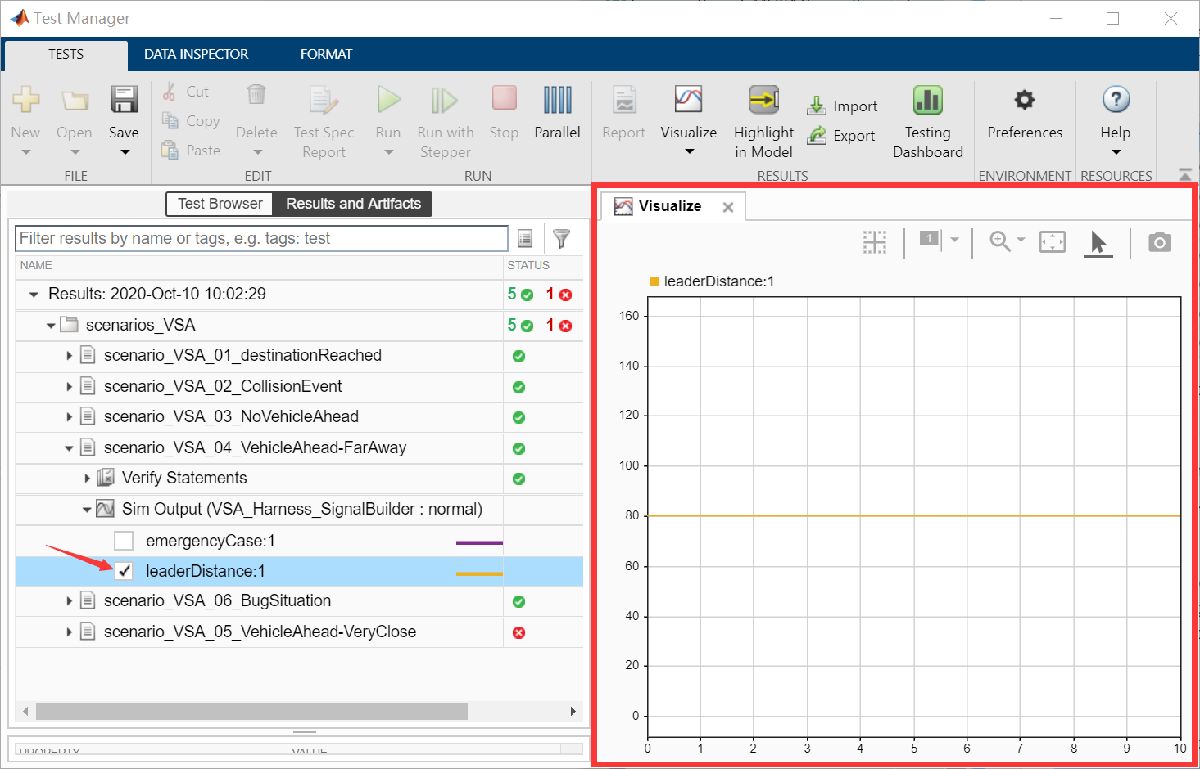

To go back to Table of Contents

## B. Generate a Test Report

After running the test cases, you can generate a test report based on the test results.

- click on the** Report** icon in the toolstrip to generete a test report:

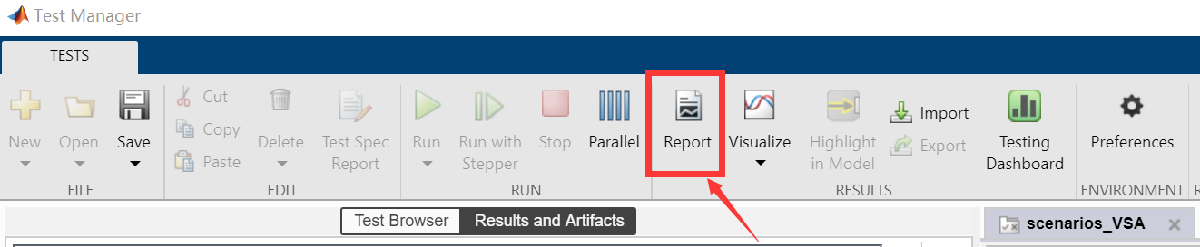

To go back to Table of Contents

## C. View the Status of the Requirements after the Tests

After running the test cases, open the Requirements Editor to view the status of the requirements. 

You can see that the **Verification Status** of the requirements linked to the test cases that **have passed** the test has changed **from yellow to green**, which means that the related requirements have been verified in the test, that is, the tested block satisfies these requirements; Conversely, the **Verification Status** of the requirements linked to the test cases that **have not passed** the test has changed **from yellow to red**, which means that the tested block does not satisfy these requirements:

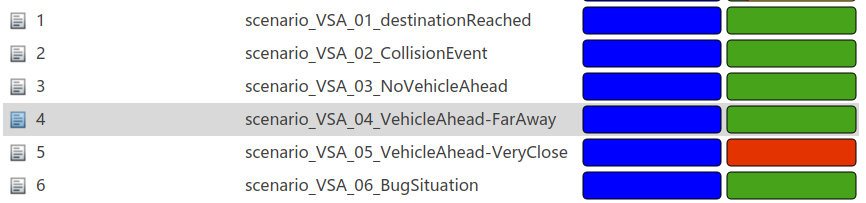

To go back to Table of Contents

# **VIII. Automated Testing**

After all the preparatory work is over, we have written an automatic test script named "`run_tests.m`". You can run this script to execute automated testing and generate test reports. First make sure that the folder is on the paths. 

You can run the test script directly using the following code:

run_tests

The automatically generated test report will also be placed in this folder. To go back to Table of Contents

# ---------------------------------------------------------------------------------

# Simulink Test Manager

The purpose of this work was to develop a testing method in MOBATSim to verify that changes in the model do not affect the different scenarios outcome.

Different than in the Model-basedTesting there are no single model components tested and therefore must not be isolated by a Test Harness Model. The tool Simulink Test Manager is to create and manage test cases and run test cases to execute tests. Logical and Temporal Assessments in Simulink® Test™ are used to verify the scenarios requirements. Functional Requirements are only made for a better overview of the things that need to be tested in each scenario.

## I     Simulink® Test™ - Overview

Simulink® Test™ provides tools for authoring, managing, and executing systematic, simulation-based tests of models, generated code, and simulated or physical hardware. It includes simulation, baseline, and equivalence test templates that let you perform functional, unit, regression, and back-to-back testing using software-in-the-loop (SIL), processor-in-the-loop (PIL), and real-time hardware-in-the-loop (HIL) modes.

With Simulink Test you can create nonintrusive test harnesses to isolate the component under test. You can define requirements-based assessments using a text-based language, and specify test input, expected outputs, and tolerances in a variety of formats, including Microsoft® Excel®. Simulink Test includes a Test Sequence block that lets you construct complex test sequences and assessments, and a test manager for managing and executing tests. Observer blocks let you access any signal in the design without changing the model or the model interface. Large sets of tests can be organized and executed in parallel or on continuous integration systems.

You can trace tests to requirements (with Simulink Requirements™) and generate reports that include test coverage information from Simulink Coverage™.

## II    Test Authoring

Start authoring tests by creating a test file in the Test Manager. Add test suites (1) for different test scenarios and test cases (2) for where you can create verification statements (Assessments) that run with your model and code.

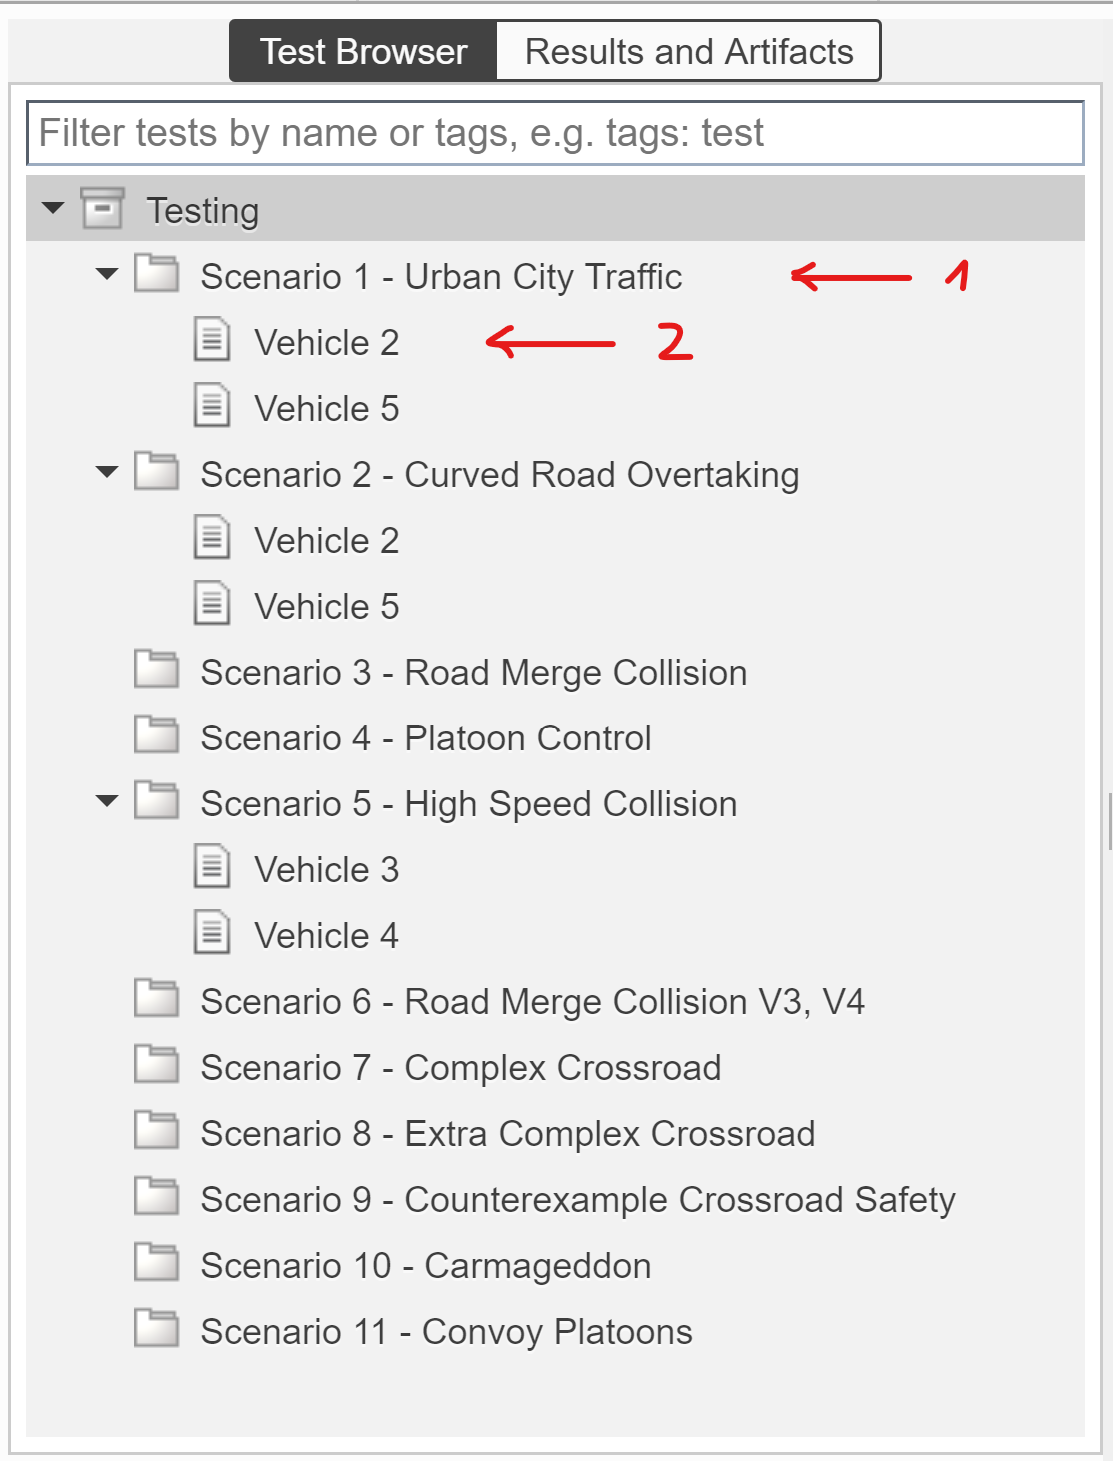

A test file can insist of multiple test suites (Szenarios). Test suites then contain the test cases. Click right on a test case to choose between four different tests: Baseline-, Equivalence-, Simulation-, and Realtime Test.

We only require the model to simulate without errors, so we will run a **Simulation Test**. The simulation test is useful if the model is still in development, or if you have an existing test model that contains inputs and assessments and logs relevant data. Using the Test Manager to run simulation tests allows you to manage numerous tests and to capture and manage results systematically.

- **!** By default, running a test in the Test Manager **disables breakpoints** for Simulink, Stateflow®, and Test Sequence blocks. Use **Run with Stepper** in the Test Manager to run a test in the simulation stepper and use the breakpoints. **!**

### **Link Test Cases**

If you use many test cases (szenarios), link to each specific test case to distinguish which blocks and test steps apply to it. To link test cases to requirements and Simulink blocks,

- Open the test case in the Test Manager.

- In the left pane, in the **Test Browser** tab, select the test case.

- In Simulink in the **Apps** tab, click **Requirements Manager**.

- To link a test case to a:

- Simulink block, right-click the block in de Simulink Model and select **Requirements** > **Link to Current Test Case** from the context menu.

- Requirement, right click on the requirement and select **Link from Selected Test Case **from the context menu.

- **or **with drag and drop 

**Info:** Requirements can be linked to Test Cases, Test Suites and/or the whole test file.

Implementation and Verification status are displayed by beams in different colors:

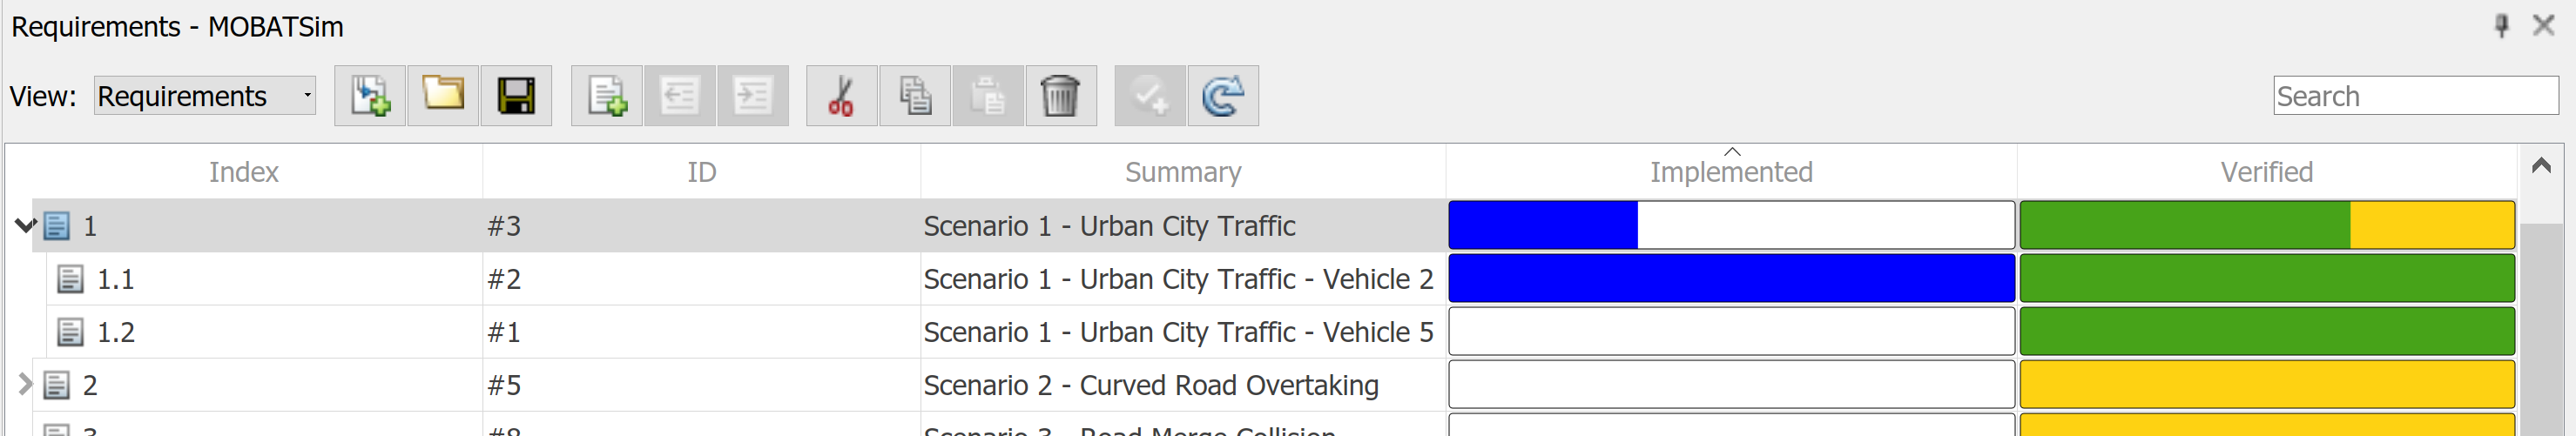

### Overview

The following image shows how a Simulation Test is structured in the Simulink® Test™ Manager:

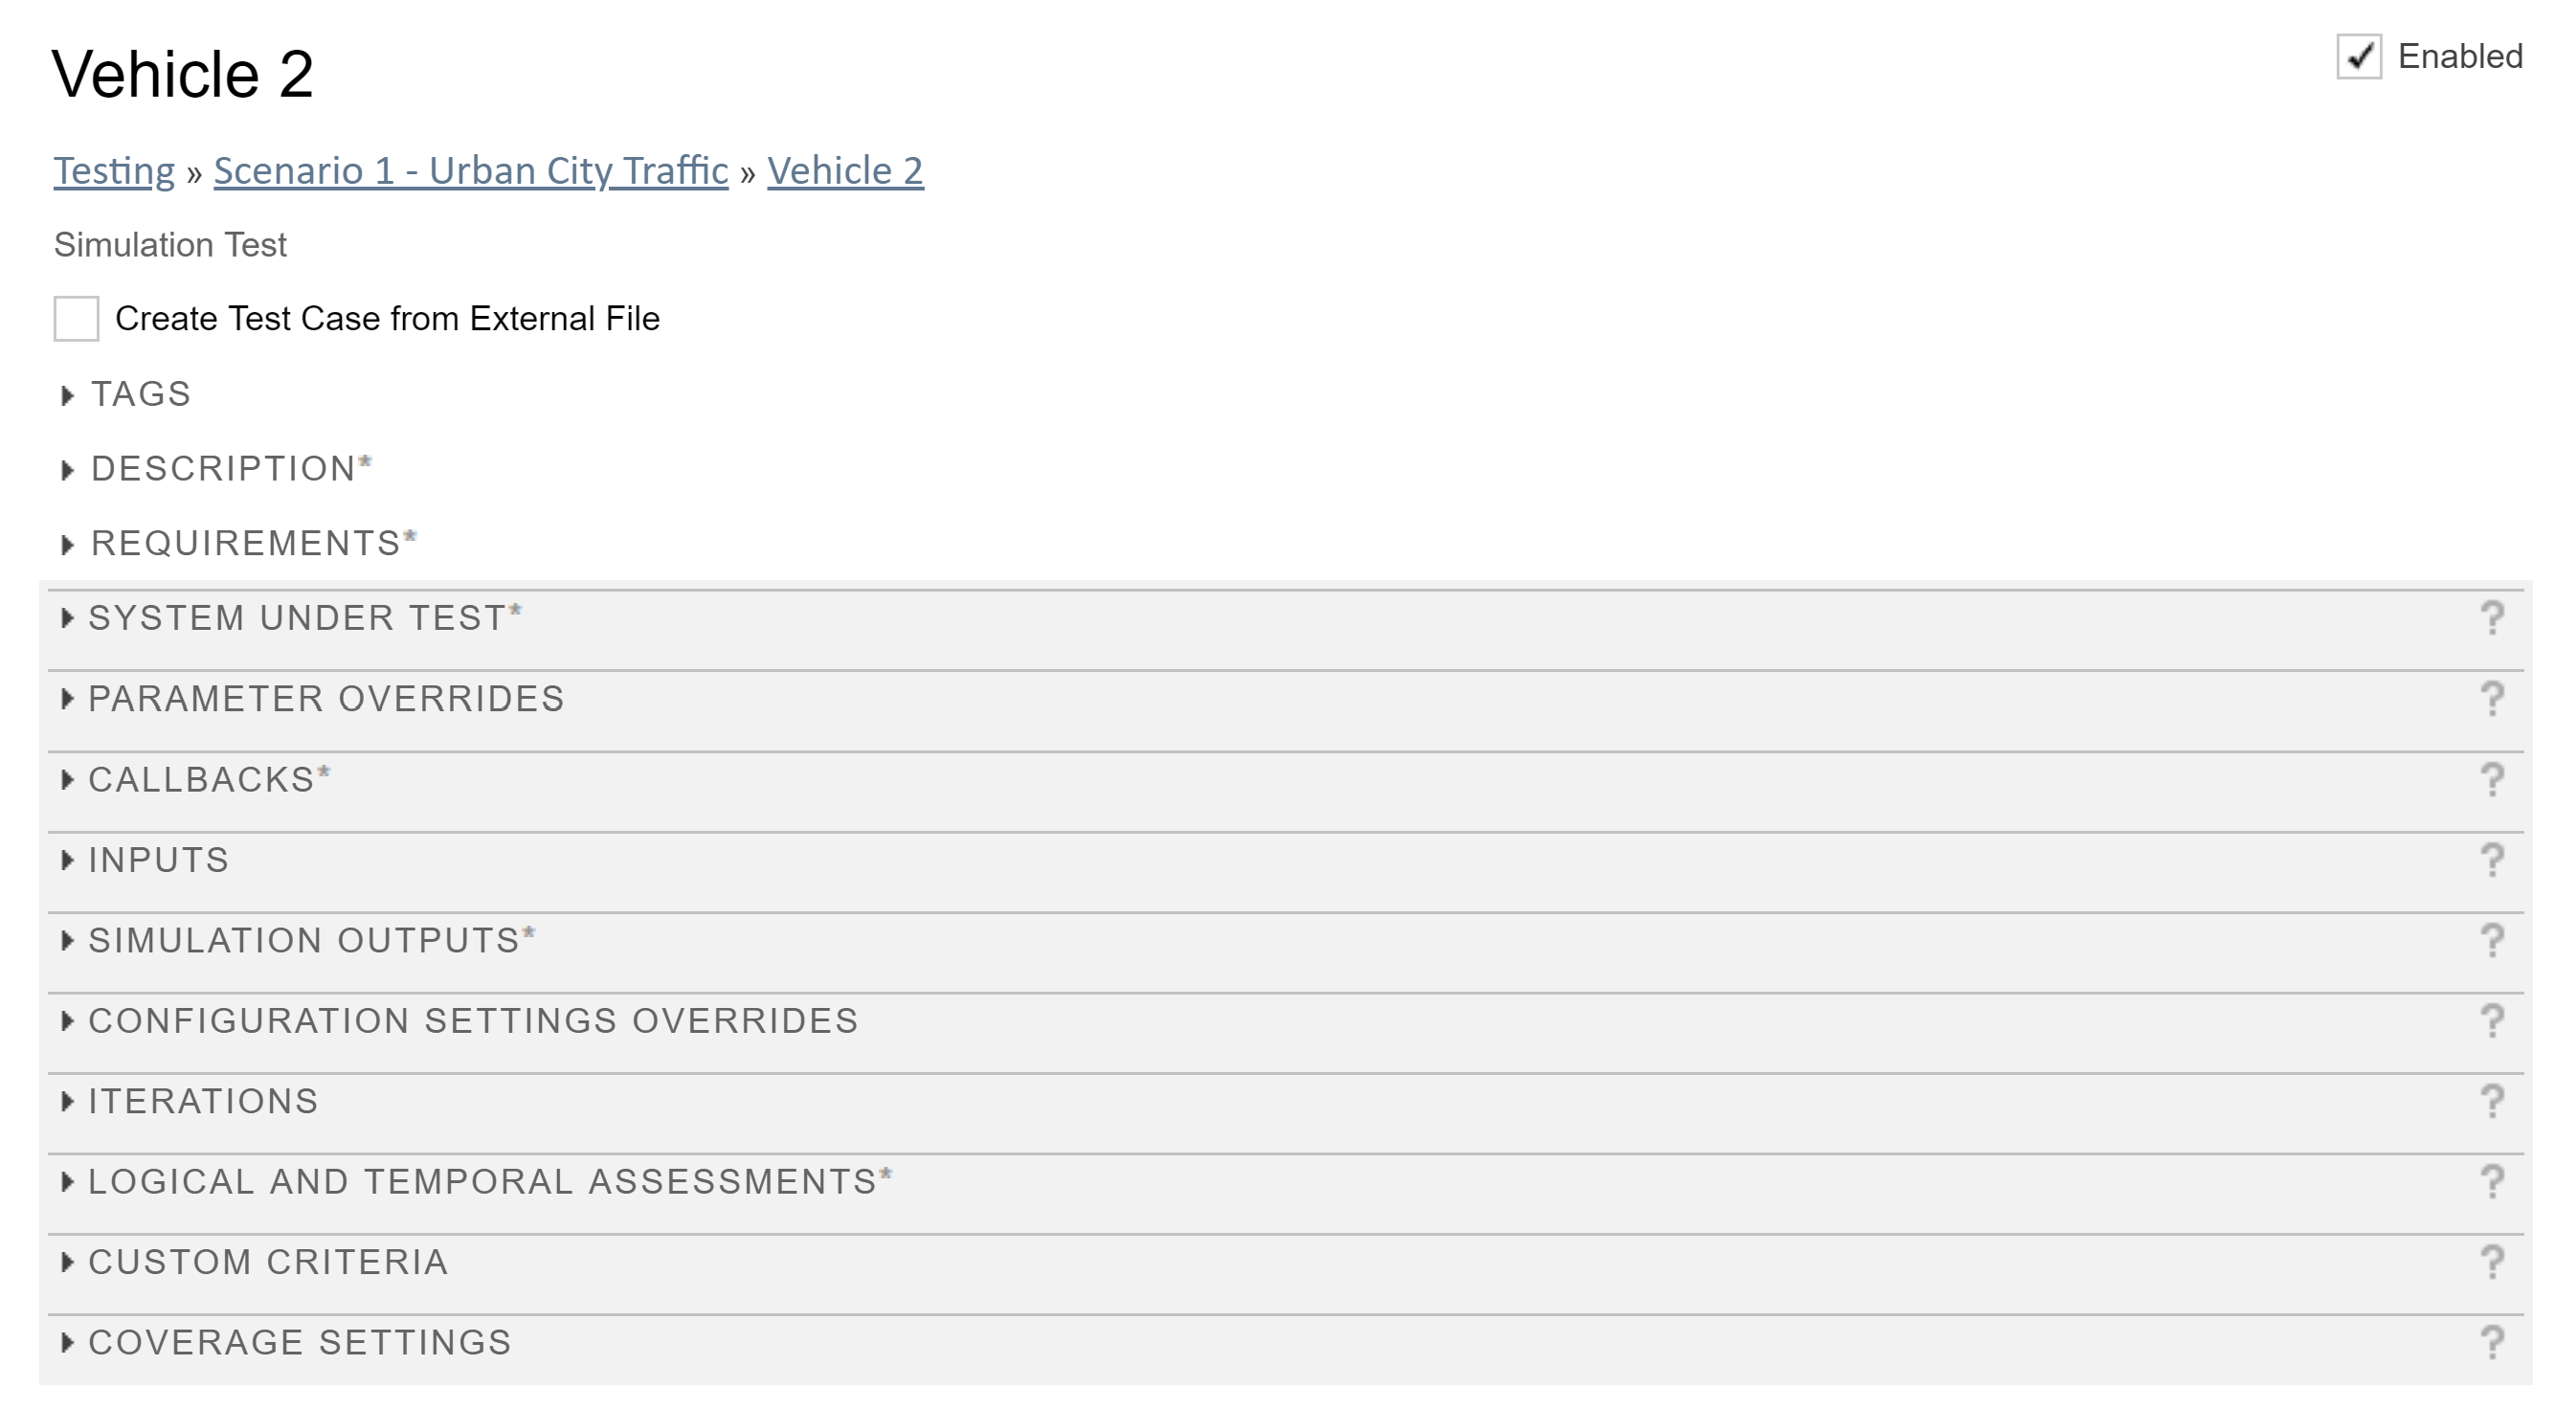

- TAGS: to filter tests when executing tests or viewing results

- REQUIREMENTS: linked requirements for better distingushing between test scenarious as described here.

- SYSTEM UNDER TEST: Choose model you want to simulate.

- **Hint:** Select 'SIMULATION SETTINGS AND RELEASE OVERRIDES' to change Simulation time, if you don't need to simulate the whole period.

- CALLBACKS: run **pre-load callback** to make sure workspace is empty and start the desired scenario: 

clear all;
prepare_simulator("scenarioName","Urban City Traffic");

- INPUTS: Define input data 

- SIMULATION OUTPUTS: Define signal outputs. They can be viewed with the Visualize button in the register or in the results and artifacts tab next to the test browser.                                                                

**Hint: Only signals** can be plotted. No simulation output of variables/data possible.

- LOGICAL AND TEMPORAL ASSESSMENTS: Assessing simulation behavior. More information how to use in the next section.

### Logical and Temporal Assessments

Functional testing includes assessing simulation behavior and comparing simulation data to expected results. You can assess simulation behavior by:

- **Using temporal and logical assessments in a test case *****- can be done without modifying the model***

- Including `verify` statements and other operators in a Test Assessment or Test Sequence block - *model needs to be modified*

- Using blocks from the Model Verification library *- model needs to be modified*

**How to work with assessments:**

- Create or open a test case in the Test Manager.

- Navigate to the **Logical and Temporal Assessments** Editor.

- Click **Add Assessment**. 

Simulink® Test™ provides two logical and one temporal assessment templates:

#### **Logical Assessment Templates**

                -    **Custom** — Check if a logical expression holds true for all time steps.

                -    **Bounds Check** — Check maximum and minimum bounds for signals and expressions

#### **Temporal Assessment Template**

**                -    Trigger-Response —** Check for a signal response when a trigger is detected

        4. Select an assessment template (Bounds Check, Custom or Trigger-response)

        5. Enter the assessment conditions.

- Map symbols to model elements, such as signals, time series, or constant. How to define symbols and variables is explained in the next section.

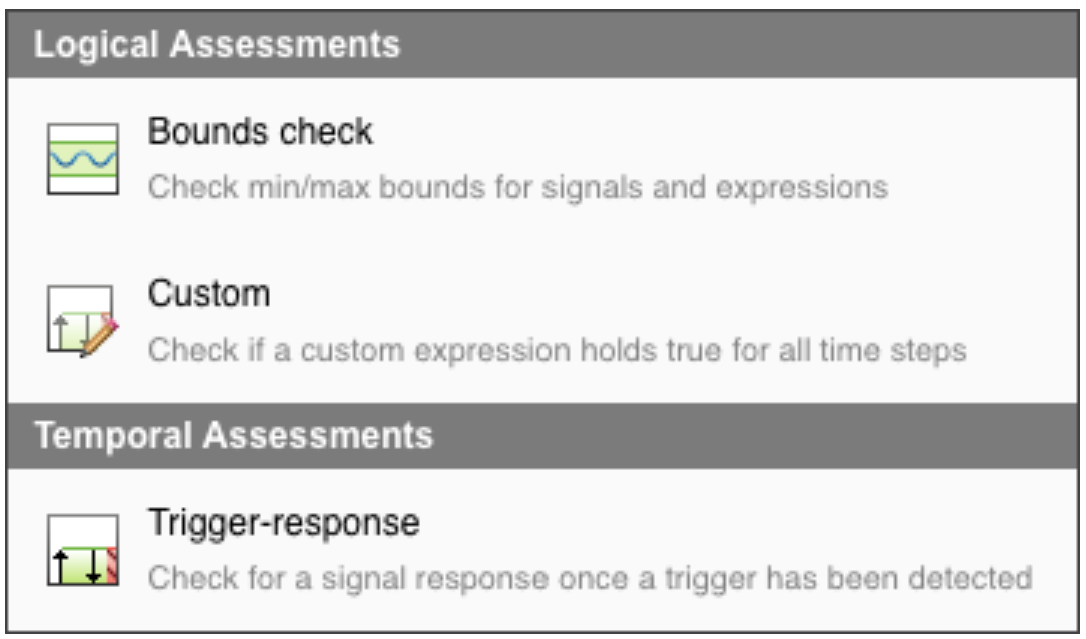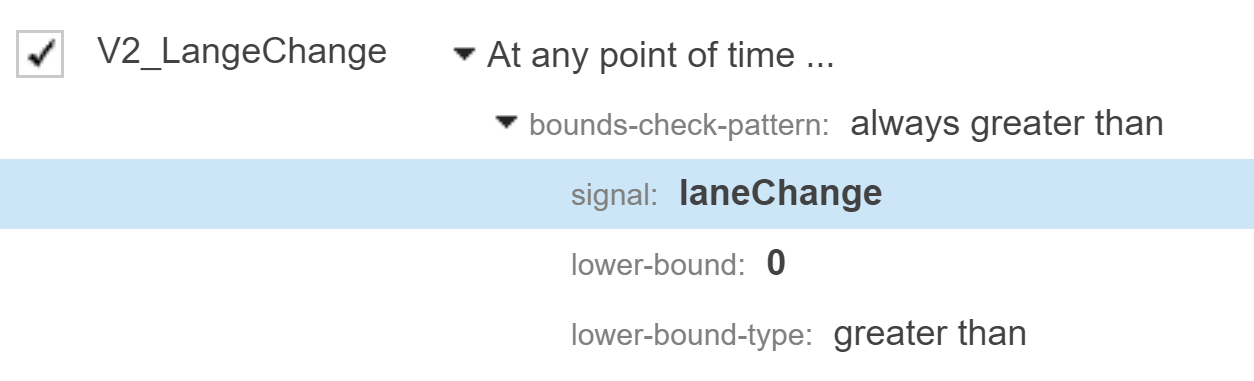

In the image above a **Bounds Check Assessment** was used to check whether the **signal laneChange** is always greater than 0. Note that statements must be true **at any point of time **for passing the test!

         6.  Run the test case.

         7.  View results in the tab '**Results and Artifacts**'

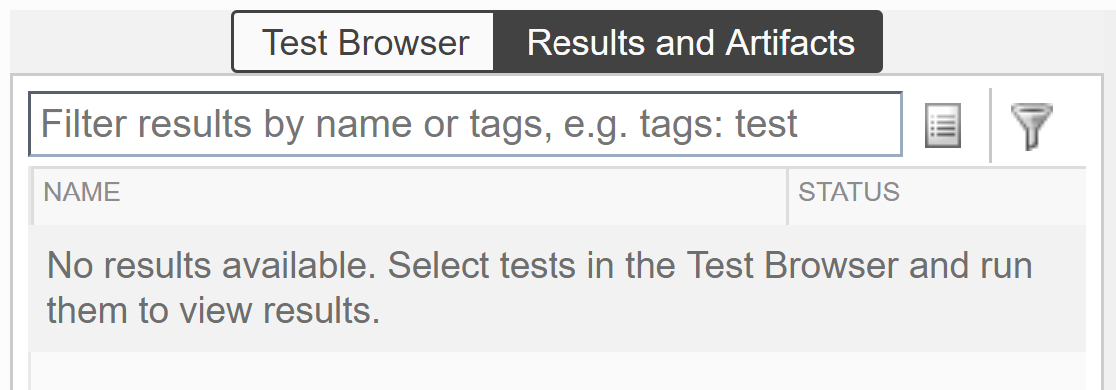

#### **Data Types in Assessment Conditions**

Logical and temporal assessment conditions support the data types listed on [Data Types Supported by Simulink](https://de.mathworks.com/help/simulink/ug/data-types-supported-by-simulink.html), with the exception of `string`. All operands in an assessment condition must be of the same data type. 

### Symbols in Assessments

In an assessment condition you can use signals, expressions, etc. from your model. In Simulink all operands must be defined as a 'Symbol' on the right side before using them. There are two ways how to resolve symbols in Simulink: Defining Variables in the Assessment Callback Section and Mapping Variables to the Model

#### **Define Variables in the Assessment Callback Section**

The **Assessment Callback** section allows you to define variables that you can use in logical and temporal assessment conditions and expressions. You can define variables the same way you do in the MATLAB workspace. This callback also has access to predefined variables that contain data from your test, model, and simulation, such as a signal from a Simulink block. You can define a variable as a function of this data.

For use in assessment conditions and expressions you need to map the symbols to the defined variables from the Callback Section: 

- On the Symbols pane click **Map to expression **

- Assign the variable defined in the Callback section

Note: The name of the symbol is the one to use for the assessment!

Note: Because the `t` symbol is automatically bound to the simulation time, you do not need to map it to an expression. `t` is not visible in the **Symbols** pane.

The variables created in the **Assessment Callback** section can only be used in conditions and expressions in the **Logical and Temporal Assessments** pane. These variables cannot be used in other areas of the Test Manager. The **Assessment Callback** is saved as part of the test file and is only resolved once at the end of simulation time.

#### **Map Symbols to model element**

You can also map symbols directly to model elemts (signals, parameters or blocks in the system under test).

- On the Symbols pane click **Map to model element **-> The simulink model will open

- Navigate to the block including your signal and select it from the drop-down list that appears when clicking on a block in the model.

- After you finish mapping symbols to model elements, the **Symbols** pane displays metadata that corresponds to the model element.

Note: You can only refer to signals that have an Input/ Output port **or** are included in the base workspace of a block. You can not reach other variables or functions defined inside the script of this block. Try using the Callback section instead.

## III    Limitations - Overview

- In the Assessment Callback it is only possible to access signals, varibales, etc. **at the end** of simulation time. 

- Therefore variables assessed with the Assessment Callback can **not be plotted**.

- Assessments only allow to verify always *true* statements. Sometimes it might be difficult to form statements this way.

- The symbols can be mapped to signals that are either input/output of a block or are in the base workspace of that block.

- Simulink Test might become more useful when it manages a great amount of test cases by keeping the overview intuitve. For only a few tests the effort might be too big.

## IV    Future Ideas

- Have a look on the stepper inside the test manager. It might be useful to access variables during the simulation. See point 1 at Limitations.

- Consider whether and to what extend a test harness block affects the simulation time.

# ---------------------------------------------------------------------------------

# Automatic Report Generation

This part is separate from the Simulink Test Manager above and presents an algorithm that generates a report in pdf, html or docx format. (Warning: Some extra data might need to be logged due to the last updates. Therefore, it might not always work correctly.)

import mlreportgen.report.*
import mlreportgen.dom.*
% Initial set of the report
name = "Test Author"
exportFormat = "pdf"
targetItem = "AEB"
scenarioName = "laneMerge"
egoVehicleSpeed =  25

## Creat a report

Rpt = Report('Safety Evaluation Report of MOBATSim', exportFormat);
% The language is related to system language
open(Rpt);

## Add Title Page


Title_page = TitlePage;
Title_page.Title = 'Safety Evaluation Report of MOBATSim -' + targetItem;
Title_page.Subtitle = 'according to ISO 26262, ISO 21448, EuroNcap'; 
Title_page.Author = 'Author: '+ name;
Title_page.Image = './image/MOBATSim_logo.png';

append(Rpt, Title_page);

## Add a table of contents

TableContent = TableOfContents();
TableContent.Title = Text('Table of Contents');
%TableContent.Title.Color = 'green';
%TableContent.NumberOfLevels = 2;
add(Rpt,TableOfContents);


## Load test data

load('test_noColiNormal.mat');
load('test_ColiNormal.mat');
load('test_noColiM1.mat');
load('test_ColiM1.mat');
load('test_noColiM2.mat');
load('test_ColiM2.mat');
load('test_noColiL1.mat');
load('test_ColiL1.mat');
load('vehicleParameter.mat');


## Add chapter and chapter sections

## Chapter 1


ch1 = Chapter; 
ch1.Title = 'Introduction'; 
para_1 = Paragraph(['This is a safety evaluation report for MOBATSim '... 
'which according to three standards: ISO 26262, ISO 21448, EuroNCAP '... 
'and generate a case study.']);
para_1.Style = {OuterMargin('0in','0in','0in','12pt')};
append(ch1,para_1);

% Add example image of the test vehicle
img_intro = FormalImage(which('.\image\vehicleStyle.png'));
img_intro.Caption = Text('Style of the test vehicle.');
add(ch1,img_intro);

% Add parameters of the test vehicle
long = VehicleParameter(3);
width = VehicleParameter(1);
height = VehicleParameter(2);
mass = VehicleParameter(4);
sensorRange = VehicleParameter(5);
AEBdistance = VehicleParameter(6);

Table_intro = table(long,width,height,mass,sensorRange,AEBdistance);
table_intro = BaseTable(Table_intro); % set table as BaseTable
table_intro.Title = 'Parameters of the vehicle';

append(ch1,table_intro);
add(Rpt,ch1);

## Chapter 2


ch2 = Chapter;
ch2.Title = 'HARA';

% Section 1 in chapter 2
sec21 = Section;

switch scenarioName
    % Scenario description for different scenarios
    case 'laneMerge'
        sec21.Title = 'Scenario definition -' + scenarioName;
        para1_ch2_sec21 = Paragraph(['The test scenario shows below '...
            'which contains two traffic paticipants drive on a merged road, '...
            'the trajectories of two vehicles are distinguished with different color .']);
        % Space to left, right, before, after.
        para1_ch2_sec21.Style = {OuterMargin('0in','0in','0in','12pt')};
        append(sec21,para1_ch2_sec21);
        
        
        % Add image
        ch2_sec21_Image_1 = FormalImage('./image/testScenario.png');
        ch2_sec21_Image_1.Caption = Text('Test Scenario in MOBATSim');
        %Image_1.Caption.Bold = true;
        %Image_1.Stype = {Height('2in'),Width('2in')};
        add(sec21,ch2_sec21_Image_1);
        
        para2_ch2_sec21 = Paragraph(['The road features of the test scenario are listed below:']);
        % Space to left, right, before, after.
        para2_ch2_sec21.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec21,para2_ch2_sec21);
        
        % Add list
        ch2_sec21_list1 = OrderedList(["Single lane","Road length","lane width 3.7m","No traffic signal and traffic signal controller"]);
        append(sec21,ch2_sec21_list1);
        
        % Add image
        ch2_sec21_Image_2 = FormalImage('./image/scenarioDefinitionOpenScenario.png');
        %ch2_sec21_Image_2.caption = Paragraph('Scenario Definition under OpenScenario');
        %Image_2_caption.Style = {%HAlign('left'),FontFamily('Arial'),...
        %FontSize('12pt'),Color('white'),...
        %BackgroundColor('blue'), ...
        % OuterMargin('0in', '0in','.0in','5pt')};
        %Image_2.Caption = Image_2_caption;
        ch2_sec21_Image_2.Caption = Text('Scenario Definition under OpenScenario');
        %Image_2.Height = '28in';
        ch2_sec21_Image_2.Width = '25in';
        %Image_1.Caption.Bold = true;
        add(sec21,ch2_sec21_Image_2);
    case 'straight'
        para_ch2_sec21_LKA = Paragraph('The test in the future.');
        % Space to left, right, before, after.
        para_ch2_sec21_LKA.Style = {OuterMargin('0in','0in','0in','12pt')};
        append(ch4,para_ch2_sec21_LKA);          
end

add(ch2,sec21);

% Section 2 in chapter 2
sec22 = Section;

switch targetItem
    case 'AEB'
        sec22.Title = 'Item Definition -' + targetItem;
        % Add image
        ch2_sec22_Image_1 = FormalImage('./image/ItemDefAEB.png');
        ch2_sec22_Image_1.Caption = Text('System block - Autonomous Emergency Brake (AEB) System in MOBATSim');
        %Image_1.Caption.Bold = true;
        %Image_1.Stype = {Height('2in'),Width('2in')};
        add(sec22,ch2_sec22_Image_1);
        % Add list
        ch2_sec22_list1 = OrderedList(["Functionality: AEB detect leading vehicle with ranging system, with the caltulation of the control system, gives the braking command to the braking system.",... 
            "Operational design domain: This AEB function is only appropriate for the MOBATSim platform, in which most of the roads are single lanes and no other vehicles drive alongside the leading vehicle."]);
        append(sec22,ch2_sec22_list1);
        
    case 'LKA'
     sec22.Title = 'Item Definition -' + targetItem;
     para_ch2 = Paragraph('can developed in the future');
     append(sec22,para_ch2);
end

add(ch2,sec22);

% Section 3 in chapter 2
sec23 = Section;
sec23.Title = 'Situation analysis and Hazard identification';
cLevel = 3; % Controlability Level, driver is out of the driving loop
switch scenarioName
    case 'laneMerge'
        % Sdd example image of the test vehicle
        image = FormalImage(which('.\image\situationalAnalysis.png'));
        image.Caption = Text('The situational analysis for specific scenario in MOBATSim');
        add(sec23,image);
        
        para_ch2_sec23 = Paragraph(['The situational analysis of the scenario "laneMerge" are listed below:']);
        % Space to left, right, before, after.
        para_ch2_sec23.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec23,para_ch2_sec23);
        
        if egoVehicleSpeed >=10 && egoVehicleSpeed<=30
        % Add list
        ch2_sec23_list1 = OrderedList(["Operational mode: normal driving.",... 
            "Operational scenario: Normal city road with single lane.",...
            "Environmental details: Normal weather (default)",...
            "Situational details: low speed (10km/h~30km/h)",...
            "Item usage: correctly used (default)"]);
        append(sec23,ch2_sec23_list1);
        eLevel = 3; % Exposure Level       
        
        para_ch2_sec23 = Paragraph('The exposure level is 3.');
        para_ch2_sec23.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec23,para_ch2_sec23);
        end
        
        if egoVehicleSpeed>30
            % Add list
             ch2_sec23_list1 = OrderedList(["Operational mode: normal driving.",... 
            "Operational scenario: Normal city road with single lane.",...
            "Environmental details: Normal weather (default)",...
            "Situational details: high speed (>30km/h)",...
            "Item usage: correctly used (default)"]);
             append(sec23,ch2_sec23_list1);
             eLevel = 3; % Exposure Level
             
             para_ch2_sec23 = Paragraph('The exposure level is 3.');
             para_ch2_sec23.Style = {OuterMargin('0in','0in','15pt','15pt')};
             append(sec23,para_ch2_sec23);
        end
        
        if egoVehicleSpeed<10
            % Add list
             ch2_sec23_list1 = OrderedList(["Operational mode: normal driving.",... 
            "Operational scenario: Normal city road with single lane.",...
            "Environmental details: Normal weather (default)",...
            "Situational details: very low speed (<10km/h)",...
            "Item usage: correctly used (default)"]);
             append(sec23,ch2_sec23_list1);
             eLevel = 3; % Exposure Level
             
             para_ch2_sec23 = Paragraph('The exposure level is 3.');
             para_ch2_sec23.Style = {OuterMargin('0in','0in','15pt','15pt')};
             append(sec23,para_ch2_sec23);
        end
        para_ch2_sec23 = Paragraph(['The hazards are caused by electronic malfunctions of target item shown below:']);
        % Space to left, right, before, after.
        para_ch2_sec23.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec23,para_ch2_sec23);
        
        ch2_sec23_Image = FormalImage('./image/malfunctions.png');
        ch2_sec23_Image.Caption = Text('The malfunctions which should happends in AEB system in MOBATSim');
        %Image_1.Caption.Bold = true;
        %Image_1.Stype = {Height('2in'),Width('2in')};
        add(sec23,ch2_sec23_Image);
        
        para_ch2_sec23 = Paragraph(['The example of hazard identification of AEB is shown below:']);
        % space to left, right, before, after.
        para_ch2_sec23.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec23,para_ch2_sec23);
        
        ch2_sec23_list = OrderedList(["Function: Autonomous Emergency Braking system shall apply a braking to slow down or stop, when there is a potential collision detected.",... 
            "Malfunction: Function not activated. Eg: the sensor does not detected the front vehicle, or there is delay time for switching driving mode.",...
            "Malfunction details: The sensor of AEB does not detected the front vehicle, so there is no input data for control system, the control system has nosignal for braking system. The AEB function does not apply a braking.",...
            "Hazardous event: The ego vehicle has a front collision with the leading vehicle.",...
            "Event details: The unactivated AEB does not apply a braking when the ego vehicle is nearing the leading vehicle, the vehicle remains at the previous speed and has a crash with leading vehicle."]);
        append(sec23,ch2_sec23_list);
        
         if egoVehicleSpeed>30
             sLevel = 3; % Severity level
             para_ch2_sec23 = Paragraph(['Collision in medium speed, the severity level is 3']);
             % Space to left, right, before, after.
             para_ch2_sec23.Style = {OuterMargin('0in','0in','15pt','15pt')};
             append(sec23,para_ch2_sec23);
         end
         
         if egoVehicleSpeed >=10 && egoVehicleSpeed<=30
            sLevel = 2; % Severity level
             para_ch2_sec23 = Paragraph(['Collision in low speed, the severity level is 2']);
             % Space to left, right, before, after.
             para_ch2_sec23.Style = {OuterMargin('0in','0in','15pt','15pt')};
             append(sec23,para_ch2_sec23);
         end
        
          if egoVehicleSpeed<10
             sLevel = 1; % Severity level
             para_ch2_sec23 = Paragraph(['Collision in very low speed, the severity level is 1']);
             % Space to left, right, before, after.
             para_ch2_sec23.Style = {OuterMargin('0in','0in','15pt','15pt')};
             append(sec23,para_ch2_sec23);  
          end
        
    case 'straight'
        para_ch2_sec23 = Paragraph(['The analysis will be done in the future']);
        % Space to left, right, before, after.
        para_ch2_sec23.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec23,para_ch2_sec23);
end


add(ch2,sec23);

% Section 4 in chapter 2
sec24 = Section;
sec24.Title = 'Hazardous event classification';

ch2_sec24_Image = FormalImage('./image/ASILlevel.png');
ch2_sec24_Image.Caption = Text('Exposure, Severity, and Controllability determin the ASIL level from low risk to high risk');
%Image_1.Caption.Bold = true;
%Image_1.Stype = {Height('2in'),Width('2in')};
add(sec24,ch2_sec24_Image);

para_ch2_sec24 = Paragraph(['According to above (Controllability level is 3, because the driver is out of the driving loop), the ASIL level of AEB in specific scenario shows below:']);
% Space to left, right, before, after.
para_ch2_sec24.Style = {OuterMargin('0in','0in','15pt','15pt')};
append(sec24,para_ch2_sec24);

% Load matrix of ASIL level with three dimension (E,C,S)
% QM = 0, ASIL A = 1, ASIL B = 2, ASIL C = 3, ASIL D = 4.
load 'ASILlevelmatrix'
if ECS(eLevel,cLevel,sLevel) ==0
   para_ch2_secsec2ASIL = Paragraph('The ASIL level is QM.');
elseif ECS(eLevel,cLevel,sLevel) ==1
   para_ch2_secsec2ASIL = Paragraph('The ASIL level is ASIL A.'); 
elseif ECS(eLevel,cLevel,sLevel) ==2
   para_ch2_secsec2ASIL = Paragraph('The ASIL level is ASIL B.');
elseif ECS(eLevel,cLevel,sLevel) ==3
   para_ch2_secsec2ASIL = Paragraph('The ASIL level is ASIL C.');
elseif ECS(eLevel,cLevel,sLevel) ==4
   para_ch2_secsec2ASIL = Paragraph('The ASIL level is ASIL D.'); 
end
append(sec24,para_ch2_secsec2ASIL)
add(ch2,sec24);

% Section 5 in chapter 2
sec25 = Section;
sec25.Title = 'Safety goal and functional safety requirement';
add(ch2,sec25);

switch targetItem
    case 'AEB'
        para_ch2_sec25 = Paragraph(['The Safety goal and functional safety requirements is shown in the list below:']);
        % Space to left, right, before, after.
        para_ch2_sec25.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec25,para_ch2_sec25);
        
        ch2_sec25_list = OrderedList(["Safety goal: The vehicle sensor of the AEB system shall reach the normal sensitivity.",...
            "Functional safety requirement 1: The AEB system shall ensure the accuracy of the algorithm in ranking system.",...
            "Malfunction details: The AEB system shall ensure the connection between vehicle model and control system has the proper functioning."]);
        append(sec25,ch2_sec25_list);
end


add(Rpt,ch2);

## Chapter 3


ch3 = Chapter;
ch3.Title = 'SOTIF';


sec31 = Section;
sec31.Title = 'Functional and System Specification';
add(ch3,sec31);

switch targetItem
    case 'AEB'
        
        para_ch3_sec31 = Paragraph(['The functional description is shown in the list below:']);
        % Space to left, right, before, after.
        para_ch3_sec31.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec31,para_ch3_sec31);
        
        ch3_sec31_list = OrderedList(["System goals: The AEB system It is responsible for detecting the leading vehicle and provides the longitudinal control to decelerate when the distance between two vehicles is shorter than the AEB distance (the distance that the AEB system is active).",...
            "Anticipated Use Case: In MOBATSim, the AEB system is activated when the ego vehicle is about to meet (distance is smaller than AEB distance) another vehicle at road merge, or drive close to near (distance is smaller than AEB distance) the front vehicle..",...
            "System Dependencies: The AEB system in MOBATSim is a relatively independent system which only relies on vehicle sensor to provide important data. It only detects the vehicles(stationary and moved), but not available for other road users and road infrastructure.",...
            ]);
        append(sec31,ch3_sec31_list);
        
        para_ch3_sec31 = Paragraph(['The system description is shown in the list below:']);
        % Space to left, right, before, after.
        para_ch3_sec31.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec31,para_ch3_sec31);
        
        ch3_sec31_list = OrderedList(["Sensor: the block Vehicle sensor in the perception part of MOBATSim is the sensor part in the AEB system, which aims to detect the front vehicle in the same route or the next route and output the leader speed and leader distance of the leading vehicle.",...
            "Longitudinal Control: The longitudinal speed control trajectory planner part of MOBATSim is the longitudinal controller in the AEB system. It takes the leader speed and leader distance as input, and output longitudinal acceleration command.",...
            "Vehicle Kinematic Model: The block Vehicle Kinematic 3DOF Single Track is taken as the actuator of the AEB system which changes the speed according to the acceleration command.",...
            ]);
        append(sec31,ch3_sec31_list);
        
        sec32 = Section;
        sec32.Title = 'Hazard Identification and Risk Assessment';
        add(ch3,sec32);
        
         para_ch3_sec32 = Paragraph(['The potential hazards are shown in the list below:']);
        % Space to left, right, before, after.
        para_ch3_sec32.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec32,para_ch3_sec32);
        
        ch3_sec32_list = OrderedList(["H1: The ego vehicle has collition with another vehicle.",...
            "H2: The ego vehicle departs from the road.",...
            ]);
        append(sec32,ch3_sec32_list);
        
        para_ch3_sec32 = Paragraph(['The potential hazardous events with Severity S>0, Controllability C>0 are shown in the list below:']);
        % Space to left, right, before, after.
        para_ch3_sec32.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec32,para_ch3_sec32);
        
        ch3_sec32_list = OrderedList(["The ego vehicle has front collition with object vehicle while performs the lane merge. (H1)",...
            "The ego vehicle has front collition with leading vehicle on the sigle lane road after the lane merge. (H1)",...
            "The ego vehicle has departs from the lane one the curved road while it tries to steering and merge to the straight road. (H2)",...
            ]);
        append(sec32,ch3_sec32_list);
        
        sec33 = Section;
        sec33.Title = 'Identification and Evaluation of Trigger Events';
        add(ch3,sec33);
        
        para_ch3_sec33 = Paragraph(['The potential triggering events are shown in the list below:']);
        % Space to left, right, before, after.
        para_ch3_sec33.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec33,para_ch3_sec33);
        
        ch3_sec33_list = OrderedList(["TE−1 The detection range of the front sensor in AEB system is limited. (H1)",...
            "TR−2 The driving mode in the sensor algorithm has relative long delay time. (H1)",...
            "TR−3 The noise interferes the proper functioning of the front sensor in AEB system. (H1)",...
            "TR − 4 The value of the minimum deceleration of the longitudinal control system is not appropriate (too big)." ,...
            ]);
        append(sec33,ch3_sec33_list);
        
        sec34 = Section;
        sec34.Title = 'Functional Modification to Reduce SOTIF Risk';
        add(ch3,sec34);
        
        para_ch3_sec34 = Paragraph(['The possible vehicle-level safety goals derived from the hazards are shown in the list below:']);
        % Space to left, right, before, after.
        para_ch3_sec34.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec34,para_ch3_sec34);
        
        ch3_sec34_list = OrderedList(["SG−1 The ego vehicle shall decclelerate early enough when approching the intersection. (H1)",...
            "SG−2 The ego vehicle shall keep a appropriate velocity while on curved road. (H2)",...
            ]);
        append(sec34,ch3_sec34_list);
        
        para_ch3_sec34 = Paragraph(['The mitigation Measures for the AEB system with relevant safety goal are shown in the list below:']);
        % Space to left, right, before, after.
        para_ch3_sec34.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(sec34,para_ch3_sec34);
        
        ch3_sec34_list = OrderedList(["MM−1 Extend the detection range of the front sensor in AEB system. (SG−1)",...
            "MM−2 Improve the sensor algotighm to a shorter reponse time. (SG−1)",...
            "MM−3 Change the minimum deceleration to a appropriate value. (SG−2)",...
            ]);
        append(sec34,ch3_sec34_list);
        
        
    case 'LKA'
        para_ch3 = Paragraph(['Comming soon']);
        % Space to left, right, before, after.
        para_ch3.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(ch3,para_ch3);
end

add(Rpt,ch3);


## Chapter 4


ch4 = Chapter;
ch4.Title = 'Case study of'+targetItem;

switch scenarioName
    case 'laneMerge'
        
        % Transform table to array for plotting
        A_Coli = table2array(T_Coli);
        A_noColi = table2array(T_noColi);
        A_noColiM1 = table2array(T_noColiM1);
        A_ColiM1 = table2array(T_ColiM1);
        A_noColiM2 = table2array(T_noColiM2);
        A_ColiM2 = table2array(T_ColiM2);
        A_noColiL1 = table2array(T_noColiL1);
        A_ColiL1 = table2array(T_ColiL1);
        
        %         % Next table start from new page
        %         br = PageBreak();
        %         append(ch4,br);
        
        % Add paragraph
        para_ch4 = Paragraph(['In this chapter, the test results of several cases are presented.'...
            ' For the sake of simplicity, only the data from vehicle_3 is shown here '...
            'The performance of the AEB is determined by KPIs: minimum TTC, minimum distance, and relative impact speed .']);
        % Space to left, right, before, after.
        para_ch4.Style = {OuterMargin('0in','0in','15pt','15pt')};
        append(ch4,para_ch4);
        
        
        % set the speed unit for categories
%         SpeedUnit_noColi = repmat("m/s",size(A_noColi,1),1);
%         SpeedUnit_Coli = repmat("m/s",size(A_Coli,1)+1, 1);
    

###         Result compare of M1 - time delay         

####          No colision                   

        sec41 = Section;
        sec41.Title = 'Test results of malfunction one: time delay in driving mode switching';
        add(ch4,sec41);
        
        % Set the speed unit for categories
         SpeedUnit_noColi = repmat("m/s",size(A_noColi,1),1);
         % Add zero to the array with malfunction when there is no data in part of this group
        groupNumber = fix(size(A_noColiM1,1)/3);
        if size(A_noColi,1)-groupNumber ==1
            if mod(size(A_noColiM1,1),3)==1
                A_noColiM1 = [A_noColiM1; zeros(1,size(A_noColiM1,2))];
                A_noColiM1 = [A_noColiM1; zeros(1,size(A_noColiM1,2))];
            elseif mod(size(A_noColiM1,1),3)==2
                A_noColiM1 = [A_noColiM1; zeros(1,size(A_noColiM1,2))];
            end
        end
        
        % Add bar graph for malfunction 1--min distance
        figure('visible','off'); % plot generation without display
        % Add all the data in the array for the bar graph
        groupM1distance = [A_noColiM1(1:3,6)];
        for i = 1:(size(A_noColi,1)-1)
            groupM1distance = [groupM1distance,[A_noColiM1(1+i*3,6);A_noColiM1(2+i*3,6);A_noColiM1(3+i*3,6)]];
        end
        barM1 = [(A_noColi(:,5))';groupM1distance]';
        
%         barM1= [A_noColi(1,5)  A_noColi(2,5)  A_noColi(3,5)  A_noColi(4,5)  A_noColi(5,5); % 0s
%             A_noColiM1(1,6) A_noColiM1(4,6) A_noColiM1(7,6) A_noColiM1(10,6) A_noColiM1(13,6); % 0.5s
%             A_noColiM1(2,6) A_noColiM1(5,6) A_noColiM1(8,6) A_noColiM1(11,6) A_noColiM1(14,6); % 1s
%             A_noColiM1(3,6) A_noColiM1(6,6) A_noColiM1(9,6) A_noColiM1(12,6) A_noColiM1(15,6)]'; % 1.5s
%         
        % Get the catagories for each groupe
        SpeedGroup = A_noColi(:,3); % Get the value of the speed
        SpeedCategories = SpeedGroup + SpeedUnit_noColi
        x = categorical(SpeedCategories');
        x = reordercats(x,SpeedCategories');
        
        bar(x,barM1,0.4);
        
        %title('The minimum distance between two vehicles under different time delay of vehicle 3');
        xlabel('speed of V3 (m/s)');
        ylabel('minimum distance');
        legend({'0s','0.5s','1s','1.5s'},'Location','northeast');
        
        
        saveas(gcf,'./image/BarM1distance.png');
        %       min_distanceM1 = Figure();
        %       min_distanceM1.Snapshot.Caption = 'The minimum distance between two vehicles under different time delay of vehicle 3. groupe 1 = 8.05m/s, groupe 2 = 7.65m/s, groupe 3 = 7.25m/s, groupe 4 = 6.85m/s, groupe 5 = 6.45m/s.';
        min_distanceM1 = FormalImage('./image/BarM1distance.png');
        min_distanceM1.Caption = Text('The minimum distance between two vehicles under different time delay of vehicle 3.');
        add(sec41,min_distanceM1);
        
        % Add bar graph for malfunction 1--min TTC
        figure('visible','off'); % plot generation without display
        
        groupM1TTC = [A_noColiM1(1:3,7)];
        for i = 1:(size(A_noColi,1)-1)
            groupM1TTC = [groupM1TTC,[A_noColiM1(1+i*3,7);A_noColiM1(2+i*3,7);A_noColiM1(3+i*3,7)]];
        end
        barM1_TTC = [(A_noColi(:,6))';groupM1TTC]';
        
%         barM1_TTC= [A_noColi(1,6)  A_noColi(2,6)  A_noColi(3,6)  A_noColi(4,6)  A_noColi(5,6); % 0s
%             A_noColiM1(1,7) A_noColiM1(4,7) A_noColiM1(7,7) A_noColiM1(10,7) A_noColiM1(13,7); % 0.5s
%             A_noColiM1(2,7) A_noColiM1(5,7) A_noColiM1(8,7) A_noColiM1(11,7) A_noColiM1(14,7); % 1s
%             A_noColiM1(3,7) A_noColiM1(6,7) A_noColiM1(9,7) A_noColiM1(12,7) A_noColiM1(15,7)]'; % 1.5s
        
        SpeedGroup = A_noColi(:,3);
        SpeedCategories = SpeedGroup + SpeedUnit_noColi
        x = categorical(SpeedCategories');
        x = reordercats(x, SpeedCategories');
        
        bar(x,barM1_TTC,0.4);
        
        %title('The minimum distance between two vehicles under different time delay of vehicle 3');
        xlabel('speed of V3 (m/s)');
        ylabel('minimum TTC');
        legend({'0s','0.5s','1s','1.5s'},'Location','northeast');
        
        saveas(gcf,'./image/BarM1TTC.png');
        %min_TTCM1 = Figure();
        %min_TTCM1.Snapshot.Caption = 'The minimum TTC under different time delay of vehicle 3. groupe 1 = 8.05m/s, groupe 2 = 7.65m/s, groupe 3 = 7.25m/s, groupe 4 = 6.85m/s, groupe 5 = 6.45m/s.';
        min_TTCM1 = FormalImage('./image/BarM1TTC.png');
        min_TTCM1.Caption = Text('The minimum TTC under different time delay of vehicle 3.');
        add(sec41,min_TTCM1);
        
        %         % without collision malfunction 2: sensor failure
        %         table_noColiM2 = BaseTable(T_noColiM2(:,[1 4:8])); % set table as BaseTable
        %         table_noColiM2.Title = 'Test result of vehicle 3 under the situation without collision with malfunction 2: sensor failure.';
        %         append(ch4,table_noColiM2);
        

#### Collision

        groupNumber = fix(size(A_ColiM1,1)/3); % The data group in T_ColiM1
        if size(A_Coli,1)-groupNumber ==0 % If there are no enough data in the first group, put it as 0
            if mod(size(A_ColiM1,1),3)==1
                A_ColiM1 = [ zeros(1,size(A_ColiM1,2));A_ColiM1];
                A_ColiM1 = [ zeros(1,size(A_ColiM1,2));A_ColiM1];
                A_Coli_bar = [zeros(1,size(A_Coli,2));A_Coli];
                % Set the speed unit for categories
                SpeedUnit_Coli = repmat("m/s",size(A_Coli,1)+1, 1); % One line of data from no collision condition may shift to this collision bar graph
                SpeedGroup =[A_noColi(end,3);A_Coli(:,3)];
            elseif mod(size(A_ColiM1,1),3)==2
                A_ColiM1 = [ zeros(1,size(A_ColiM1,2));A_ColiM1];
                A_Coli_bar = [zeros(1,size(A_Coli,2));A_Coli];
                % Set the speed unit for categories
                SpeedUnit_Coli = repmat("m/s",size(A_Coli,1)+1, 1);
                SpeedGroup =[A_noColi(end,3);A_Coli(:,3)];
            elseif mod(size(A_ColiM1,1),3)==0 % If the speed group are the same
                A_Coli_bar = A_Coli;
                 % Set the speed unit for categories
                SpeedUnit_Coli = repmat("m/s",size(A_Coli,1), 1);
                SpeedGroup =A_Coli(:,3);    
            end
        elseif groupNumber-size(A_Coli,1) ==1
            A_Coli_bar = [zeros(1,size(A_Coli,2));A_Coli];
            % Set the speed unit for categories
            SpeedUnit_Coli = repmat("m/s",size(A_Coli,1)+1, 1);
            SpeedGroup =[A_noColi(end,3);A_Coli(:,3)];
        end   
        
        figure('visible','off'); % plot generation without display
        % Get the data for bar graph
        groupM1Impa = [A_ColiM1(1:3,6)];
        for i = 1:(size(A_Coli_bar,1)-1)
            groupM1Impa = [groupM1Impa,[A_ColiM1(1+i*3,6);A_ColiM1(2+i*3,6);A_ColiM1(3+i*3,6)]];
        end
        
        barM1_impa = [(A_Coli_bar(:,5))';groupM1Impa]';
        
%         barM1_impa= [0 A_Coli(1,5)  A_Coli(2,5)  A_Coli(3,5)  A_Coli(4,5); % 0s
%             A_ColiM1(1,6) A_ColiM1(4,6) A_ColiM1(7,6) A_ColiM1(10,6) A_ColiM1(13,6); % 0.5s
%             A_ColiM1(2,6) A_ColiM1(5,6) A_ColiM1(8,6) A_ColiM1(11,6) A_ColiM1(14,6); % 1s
%             A_ColiM1(3,6) A_ColiM1(6,6) A_ColiM1(9,6) A_ColiM1(12,6) A_ColiM1(15,6)]'; % 1.5s
        
        
        SpeedCategories = SpeedGroup + SpeedUnit_Coli
        x = categorical(SpeedCategories');
        x = reordercats(x,SpeedCategories');
        
        bar(x,barM1_impa,0.4);
        
        %title('The minimum distance between two vehicles under different time delay of vehicle 3');
        xlabel('speed of V3 (m/s)');
        ylabel('relavive impact speed');
        legend({'0s','0.5s','1s','1.5s'},'Location','northwest');
        
        saveas(gcf,'./image/BarM1relaImpact.png');
        %       min_distanceM1 = Figure();
        %       min_distanceM1.Snapshot.Caption = 'The minimum distance between two vehicles under different time delay of vehicle 3. groupe 1 = 8.05m/s, groupe 2 = 7.65m/s, groupe 3 = 7.25m/s, groupe 4 = 6.85m/s, groupe 5 = 6.45m/s.';
        rela_impaM1 = FormalImage('./image/BarM1relaImpact.png');
        rela_impaM1.Caption = Text('The relative impact speed between two vehicles under different time delay of vehicle 3.');
        add(sec41,rela_impaM1);
        
        

###   Result compare of M2 - sensor failure

#### No collision

        sec42 = Section;
        sec42.Title = 'Test results of malfunction two: sensor failure';
        add(ch4,sec42);
       
        groupNumber = fix(size(A_noColiM2,1)/4); % the data group in T_noColiM2
        
        % Set the speed unit for categories
         SpeedUnit_noColi = repmat("m/s",size(A_noColi,1),1);

        if size(A_noColi,1)-groupNumber ==1 % If there are no enough line in the last group, put it as 0;
            if mod(size(A_noColiM2,1),4)==1
                A_noColiM2 = [A_noColiM2; zeros(1,size(A_noColiM2,2))];
                A_noColiM2 = [A_noColiM2; zeros(1,size(A_noColiM2,2))];
                A_noColiM2 = [A_noColiM2; zeros(1,size(A_noColiM2,2))];
            elseif mod(size(A_noColiM2,1),4)==2
                A_noColiM2 = [A_noColiM2; zeros(1,size(A_noColiM2,2))];
                A_noColiM2 = [A_noColiM2; zeros(1,size(A_noColiM2,2))];
            elseif mod(size(A_noColiM2,1),4)==3
                A_noColiM2 = [A_noColiM2; zeros(1,size(A_noColiM2,2))];
            end
        end
        
        % Add bar graph of min distance for malfunction 2
        figure('visible','off'); % plot generation without display
        
        groupM2distance = [A_noColiM2(1:4,6)];
        for i = 1:(size(A_noColi,1)-1)
            groupM2distance = [groupM2distance,[A_noColiM2(1+i*4,6);A_noColiM2(2+i*4,6);A_noColiM2(3+i*4,6);A_noColiM2(4+i*4,6)]];
        end
        barM2 = [(A_noColi(:,5))';groupM2distance]';       
        
%         barM2 =[A_noColi(1,5)  A_noColi(2,5)  A_noColi(3,5)  A_noColi(4,5)  A_noColi(5,5); % 0
%             A_noColiM2(1,6) A_noColiM2(5,6) A_noColiM2(9,6) A_noColiM2(13,6) A_noColiM2(17,6); % 0.3
%             A_noColiM2(2,6) A_noColiM2(6,6) A_noColiM2(10,6) A_noColiM2(14,6) A_noColiM2(18,6); % 0.5
%             A_noColiM2(3,6) A_noColiM2(7,6) A_noColiM2(11,6) A_noColiM2(15,6) A_noColiM2(19,6); % 0.7
%             A_noColiM2(4,6) A_noColiM2(8,6) A_noColiM2(12,6) A_noColiM2(16,6) A_noColiM2(20,6);]'; % 0.9
        
        SpeedGroup = A_noColi(:,3);
        SpeedCategories = SpeedGroup + SpeedUnit_noColi
        x = categorical(SpeedCategories');
        x = reordercats(x,SpeedCategories');
        
        bar(x,barM2,0.4);
        
        %title('The minimum distance between two vehicles under different time delay of vehicle 3');
        xlabel('speed of V3 (m/s)');
        ylabel('minimum distance');
        legend({'0','0.3','0.5','0.7','0.9'},'Location','northeast');
        
        saveas(gcf,'./image/BarM2distance.png');
        %min_distanceM2 = Figure();
        %min_distanceM2.Snapshot.Caption = 'The minimum distance between two vehicles under different failure rate of vehicle 3. groupe 1 = 8.05m/s, groupe 2 = 7.65m/s, groupe 3 = 7.25m/s, groupe 4 = 6.85m/s, groupe 5 = 6.45m/s.';
        min_distanceM2 = FormalImage('./image/BarM2distance.png');
        min_distanceM2.Caption = Text('The minimum distance between two vehicles under different failure rate of vehicle 3.');
        add(sec42,min_distanceM2);
        %delete(gcf);
        
        
        % Add bar graph of min TTC for malfunction 2
        figure('visible','off'); % plot generation without display
        
        groupM2TTC = [A_noColiM2(1:4,7)];
        for i = 1:(size(A_noColi,1)-1)
            groupM2TTC = [groupM2TTC,[A_noColiM2(1+i*4,7);A_noColiM2(2+i*4,7);A_noColiM2(3+i*4,7);A_noColiM2(4+i*4,7)]];
        end
        barM2_TTC = [(A_noColi(:,6))';groupM2TTC]';
        bar(barM2_TTC,0.4);
       
%         barM2_TTC =[A_noColi(1,6)  A_noColi(2,6)  A_noColi(3,6)  A_noColi(4,6)  A_noColi(5,6); % 0
%             A_noColiM2(1,7) A_noColiM2(5,7) A_noColiM2(9,7) A_noColiM2(13,7) A_noColiM2(17,7); % 0.3
%             A_noColiM2(2,7) A_noColiM2(6,7) A_noColiM2(10,7) A_noColiM2(14,7) A_noColiM2(18,7); % 0.5
%             A_noColiM2(3,7) A_noColiM2(7,7) A_noColiM2(11,7) A_noColiM2(15,7) A_noColiM2(19,7); % 0.7
%             A_noColiM2(4,7) A_noColiM2(8,7) A_noColiM2(12,7) A_noColiM2(16,7) A_noColiM2(20,7);]'; % 0.9
        
        SpeedGroup = A_noColi(:,3);
        SpeedCategories = SpeedGroup + SpeedUnit_noColi
        x = categorical(SpeedCategories');
        x = reordercats(x,SpeedCategories');
        
        bar(x,barM2_TTC,0.4);
        
        %title('The minimum distance between two vehicles under different time delay of vehicle 3');
        xlabel('speed of V3 (m/s)');
        ylabel('minimum TTC');
        legend({'0','0.3','0.5','0.7','0.9'},'Location','northeast');
        
        saveas(gcf,'./image/BarM2TTC.png');
        %min_TTCM2 = Figure();
        %min_TTCM2.Snapshot.Caption = 'The minimum TTC under different failure rate of vehicle 3. groupe 1 = 8.05m/s, groupe 2 = 7.65m/s, groupe 3 = 7.25m/s, groupe 4 = 6.85m/s, groupe 5 = 6.45m/s.';
        min_TTCM2 = FormalImage('./image/BarM2TTC.png');
        min_TTCM2.Caption = Text('The minimum TTC under different failure rate of vehicle 3.');
        add(sec42,min_TTCM2);
        %delete(gcf);
        
        

#### Collision

        groupNumber = fix(size(A_ColiM2,1)/4); % The data group in T_ColiM2
        if size(A_Coli,1)-groupNumber ==0 % If there are no enough line in the last group, put it as 0;
            if mod(size(A_ColiM2,1),4)==1
                A_ColiM2 = [ zeros(1,size(A_ColiM2,2));A_ColiM2];
                A_ColiM2 = [ zeros(1,size(A_ColiM2,2));A_ColiM2];
                A_ColiM2 = [ zeros(1,size(A_ColiM2,2));A_ColiM2];
                A_Coli_bar = [zeros(1,size(A_Coli,2));A_Coli];
                % Set the speed unit for categories
                SpeedUnit_Coli = repmat("m/s",size(A_Coli,1)+1, 1); % One line of data from no collision condition may shift to this collision bar graph
                SpeedGroup =[A_noColi(end,3);A_Coli(:,3)];
            elseif mod(size(A_ColiM2,1),4)==2
                A_ColiM2 = [ zeros(1,size(A_ColiM2,2));A_ColiM2];
                A_ColiM2 = [ zeros(1,size(A_ColiM2,2));A_ColiM2];
                A_Coli_bar = [zeros(1,size(A_Coli,2));A_Coli];
                % Set the speed unit for categories
                SpeedUnit_Coli = repmat("m/s",size(A_Coli,1)+1, 1);
                SpeedGroup =[A_noColi(end,3);A_Coli(:,3)];
            elseif mod(size(A_ColiM2,1),4)==3
                A_ColiM2 = [ zeros(1,size(A_ColiM2,2));A_ColiM2];
                A_Coli_bar = [zeros(1,size(A_Coli,2));A_Coli];
                % Set the speed unit for categories
                SpeedUnit_Coli = repmat("m/s",size(A_Coli,1)+1, 1);
                SpeedGroup =[A_noColi(end,3);A_Coli(:,3)];
            elseif mod(size(A_ColiM2,1),4)==0 % The number of speed groups are the same
                A_Coli_bar = A_Coli;
                % Set the speed unit for categories
                SpeedUnit_Coli = repmat("m/s",size(A_Coli,1), 1);
                SpeedGroup =A_Coli(:,3);
            end
        elseif groupNumber-size(A_Coli,1) ==1
            A_Coli_bar = [zeros(1,size(A_Coli,2));A_Coli];
            SpeedGroup =[A_noColi(end,3);A_Coli(:,3)];
        end
        
        figure('visible','off'); % Plot generation without display
        
        groupM2Impa = [A_ColiM2(1:4,6)];
        for i = 1:(size(A_Coli_bar,1)-1)
            groupM2Impa = [groupM2Impa,[A_ColiM2(1+i*4,6);A_ColiM2(2+i*4,6);A_ColiM2(3+i*4,6);A_ColiM2(4+i*4,6)]];
        end
        barM2_impa = [(A_Coli_bar(:,5))';groupM2Impa]';
        
%         barM2_impa= [0 A_Coli(1,5)  A_Coli(2,5)  A_Coli(3,5)  A_Coli(4,5); % 0s
%             A_ColiM2(1,6) A_ColiM2(5,6) A_ColiM2(9,6) A_ColiM2(13,6) A_ColiM2(17,6); % 0.5s
%             A_ColiM2(2,6) A_ColiM2(6,6) A_ColiM2(10,6) A_ColiM2(14,6) A_ColiM2(18,6); % 1s
%             A_ColiM2(3,6) A_ColiM2(7,6) A_ColiM2(11,6) A_ColiM2(15,6) A_ColiM2(19,6);
%             A_ColiM2(4,6) A_ColiM2(8,6) A_ColiM2(12,6) A_ColiM2(16,6) A_ColiM2(20,6)]'; % 1.5s
%         
        
        SpeedCategories = SpeedGroup + SpeedUnit_Coli
        x = categorical(SpeedCategories');
        x = reordercats(x,SpeedCategories');
        
        bar(x,barM2_impa,0.4);
        
        %title('The minimum distance between two vehicles under different time delay of vehicle 3');
        xlabel('speed of V3 (m/s)');
        ylabel('relavive impact speed');
        legend({'0','0.3','0.5','0.7','0.9'},'Location','northwest');
        
        saveas(gcf,'./image/BarM2relaImpact.png');
        %       min_distanceM1 = Figure();
        %       min_distanceM1.Snapshot.Caption = 'The minimum distance between two vehicles under different time delay of vehicle 3. groupe 1 = 8.05m/s, groupe 2 = 7.65m/s, groupe 3 = 7.25m/s, groupe 4 = 6.85m/s, groupe 5 = 6.45m/s.';
        rela_impaM2 = FormalImage('./image/BarM2relaImpact.png');
        rela_impaM2.Caption = Text('The relative impact speed between two vehicles under different failure rate of vehicle 3.');
        add(sec42,rela_impaM2);
        

### Limitation - constant time delay

#### No collision

        sec43 = Section;
        sec43.Title = 'Test results of malfunction one: time delay in driving mode switching';
        add(ch4,sec43);
        
        % Set the speed unit for categories
         SpeedUnit_noColi = repmat("m/s",size(A_noColi,1),1);
        % If there are no enough line in the array with data from limitation, put it as 0;
        if size(A_noColi,1)-size(A_noColiL1,1)==1
            A_noColiL1 = [A_noColiL1; zeros(1,size(A_noColiL1,2))]
        elseif size(A_noColi,1)-size(A_nocoliL1,1)==2
            A_noColiL1 = [A_noColiL1; zeros(1,size(A_noColiL1,2))];
            A_noColiL1 = [A_noColiL1; zeros(1,size(A_noColiL1,2))];
        elseif size(A_noColi,1)-size(A_nocoliL1,1)==3
            A_noColiL1 = [A_noColiL1; zeros(1,size(A_noColiL1,2))];
            A_noColiL1 = [A_noColiL1; zeros(1,size(A_noColiL1,2))];
            A_noColiL1 = [A_noColiL1; zeros(1,size(A_noColiL1,2))];
        end
        
        % Add bar graph of min distance for limitation 1
        figure('visible','off'); % plot generation without display
        groupM1distance = [];
        for i = 1:size(A_noColi,1)
            groupM1distance = [groupM1distance;A_noColiL1(i,6)];
        end
        barL1 = [(A_noColi(:,5))';groupM1distance']';
        
%         barL1 =[A_noColi(1,5)  A_noColi(2,5)  A_noColi(3,5)  A_noColi(4,5)  A_noColi(5,5); % 0
%             A_noColiL1(1,6) A_noColiL1(2,6) A_noColiL1(3,6) A_noColiL1(4,6) A_noColiL1(5,6)]'; % 2s
       
        SpeedGroup = A_noColi(:,3);
        SpeedCategories = SpeedGroup + SpeedUnit_noColi
        x = categorical(SpeedCategories');
        x = reordercats(x,SpeedCategories');
        
        bar(x,barL1);
        %title('The minimum distance between two vehicles under different time delay of vehicle 3');
        xlabel('speed of V3 (m/s)');
        ylabel('minimum distance');
        legend({'0s','2s'},'Location','northeast');
        
        saveas(gcf,'./image/barL1distance.png');
        %min_distanceL1 = Figure();
        %min_distanceL1.Snapshot.Caption = 'The minimum distance between two vehicles under sensor limitation-time delay of 2s.';
        min_distanceL1 = FormalImage('./image/barL1distance.png');
        min_distanceL1.Caption = Text('The minimum distance between two vehicles under sensor limitation-time delay of 2s.');
        add(sec43,min_distanceL1);
        %delete(gcf);
        
        
        % Add bar graph of min distance for limitation 1
        figure('visible','off'); % plot generation without display
        
        groupL1TTC=[];
        for i = 1:size(A_noColi,1)
            groupL1TTC = [groupL1TTC;A_noColiL1(i,7)];
        end
        barL1_TTC = [(A_noColi(:,6))';groupL1TTC']';
        
%         barL1_TTC =[A_noColi(1,6)  A_noColi(2,6)  A_noColi(3,6)  A_noColi(4,6)  A_noColi(5,6); % 0
%             A_noColiL1(1,7) A_noColiL1(2,7) A_noColiL1(3,7) A_noColiL1(4,7) A_noColiL1(5,7)]'; % 2s
        
        SpeedGroup = A_noColi(:,3);
        SpeedCategories = SpeedGroup + SpeedUnit_noColi
        x = categorical(SpeedCategories');
        x = reordercats(x,SpeedCategories');
        
        bar(x,barL1_TTC);
        %title('The minimum distance between two vehicles under different time delay of vehicle 3');
        xlabel('speed of V3 (m/s)');
        ylabel('minimum TTC');
        legend({'0s','2s'},'Location','northeast');
        
        saveas(gcf,'./image/barL1TTC.png');
        %         min_TTCL1 = Figure();
        %         min_TTCL1.Snapshot.Caption = 'The minimum TTC under sensor limitation-time delay of 2s.';
        min_TTCL1 = FormalImage('./image/barL1TTC.png');
        min_TTCL1.Caption = Text('The minimum TTC under sensor limitation-time delay of 2s.');
        add(sec43,min_TTCL1);
        %delete(gcf);
        
        

#### Collision

        if size(A_ColiL1,1)-size(A_Coli,1)==1
            A_Coli_bar = [zeros(1,size(A_Coli,2));A_Coli];
            % Set the speed unit for categories
            SpeedUnit_Coli = repmat("m/s",size(A_Coli,1)+1, 1); % One line of data from no collision condition may shift to this collision bar graph
            SpeedGroup =[A_noColi(end,3);A_Coli(:,3)];
        elseif size(A_ColiL1,1)-size(A_Coli,1)==2
            A_Coli_bar = [zeros(1,size(A_Coli,2));A_Coli];
            A_Coli_bar = [zeros(1,size(A_Coli,2));A_Coli];
            % Set the speed unit for categories
            SpeedUnit_Coli = repmat("m/s",size(A_Coli,1)+1, 1);
            SpeedGroup =[A_noColi(end,3);A_Coli(:,3)];
        elseif size(A_ColiL1,1)-size(A_Coli,1)==3
            A_Coli_bar = [zeros(1,size(A_Coli,2));A_Coli];
            A_Coli_bar = [zeros(1,size(A_Coli,2));A_Coli];
            A_Coli_bar = [zeros(1,size(A_Coli,2));A_Coli];
            % Set the speed unit for categories
            SpeedUnit_Coli = repmat("m/s",size(A_Coli,1)+1, 1);
            SpeedGroup =[A_noColi(end,3);A_Coli(:,3)];
        elseif size(A_ColiL1,1)-size(A_Coli,1)==0
            A_Coli_bar = A_Coli;
            % Set the speed unit for categories
            SpeedUnit_Coli = repmat("m/s",size(A_Coli,1), 1);
            SpeedGroup =A_Coli(:,3);
        end
        
        figure('visible','off'); % Plot generation without display
        
        groupL1Impa = [];
        for i = 1:size(A_Coli_bar,1)
            groupL1Impa = [ groupL1Impa;A_ColiL1(i,6)];
        end
        barL1_impa = [(A_Coli_bar(:,5))'; groupL1Impa']';
%         barL1_impa= [0 A_Coli(1,5)  A_Coli(2,5)  A_Coli(3,5)  A_Coli(4,5); % 0s
%             A_ColiL1(1,6) A_ColiL1(2,6) A_ColiL1(3,6) A_ColiL1(4,6) A_ColiL1(5,6)];  % 2s
        
       
        SpeedCategories = SpeedGroup + SpeedUnit_Coli;
        x = categorical(SpeedCategories');
        x = reordercats(x,SpeedCategories');
        
        bar(x,barL1_impa);
        
        %title('The minimum distance between two vehicles under different time delay of vehicle 3');
        xlabel('speed of V3 (m/s)');
        ylabel('relavive impact speed');
        legend({'0s','2s'},'Location','northwest');
        
        saveas(gcf,'./image/BarL1relaImpact.png');
        %       min_distanceM1 = Figure();
        %       min_distanceM1.Snapshot.Caption = 'The minimum distance between two vehicles under different time delay of vehicle 3. groupe 1 = 8.05m/s, groupe 2 = 7.65m/s, groupe 3 = 7.25m/s, groupe 4 = 6.85m/s, groupe 5 = 6.45m/s.';
        rela_impaL1 = FormalImage('./image/BarL1relaImpact.png');
        rela_impaL1.Caption = Text('The relative impact speed between two vehicles under sensor limitation-time delay of 2s.');
        add(sec43,rela_impaL1);
                      

###   AEB score according to EuroNCAP

        sec44 = Section;
        sec44.Title = ' AEB score according to EuroNCAP';
        add(ch4,sec44);
        % The speed of test vehicle in color scheme (CCRm) of EuroNCAP
        VUTtestSpeed = [30 35 40 45 50 55 60 65 70 75 80 85]; % km/h
        % Get maximal speed of test vehicle
        V3MaxSpeed = [A_noColi(:,3); A_Coli(:,3)]';
        selectSpeed = [];
        vehicleSpeed = [];
        
            for i = 1:size(VUTtestSpeed,2) % Find the same speed as in EuroNCAP color scheme
                for j =1: size(V3MaxSpeed,2)
                    if (3.6*V3MaxSpeed(j)>VUTtestSpeed(i)-0.1)&& (3.6*V3MaxSpeed(j)<VUTtestSpeed(i)+0.1)
                        selectSpeed = [selectSpeed,VUTtestSpeed(i)];
                        vehicleSpeed = [vehicleSpeed,V3MaxSpeed(j)]; % The vehicle speed that is the same as the color scheme  
                    end
                end
                
            end
            
            relImpactSum = [];
            for i = 1: size(vehicleSpeed) % Select corresponding relative impact speed from all the data array with collision conditions
                for j = 1:size(A_Coli)
                    if A_Coli(j,3) == vehicleSpeed(i)
                     relImpactSum = [relImpactSum;vehicleSpeed(i),0, A_Coli(j,5)]; %[vehiclespeed, no malfunction, relaImpactspeed]     
                    end
                end
                
                for j = 1:size(A_ColiM1)
                    if A_ColiM1(j,4) == vehicleSpeed(i)
                     relImpactSum = [relImpactSum; vehicleSpeed(i), A_ColiM1(j,1), A_ColiM1(j,6)]; %[vehiclespeed, malfunction 1, relaImpactspeed]     
                    end
                end
                
                for j = 1:size(A_ColiM2)
                    if A_ColiM2(j,4) == vehicleSpeed(i)
                     relImpactSum = [relImpactSum; vehicleSpeed(i), A_ColiM2(j,1), A_ColiM2(j,6)]; %[vehiclespeed, malfunction 2, relaImpactspeed]     
                    end
                end
                
                for j = 1:size(A_ColiL1)
                    if A_ColiL1(j,4) == vehicleSpeed(i)
                     relImpactSum = [relImpactSum; vehicleSpeed(i), A_ColiL1(j,1), A_ColiL1(j,6)]; %[vehiclespeed, limitation, relaImpactspeed]     
                    end
                end
                relImpactSum = [3.6,1,3.6].*relImpactSum % Unit transformation from m/s to km/h
                
                % Score according to color scheme (CCRm)
                if (relImpactSum(1,1)>30-0.1)&& (relImpactSum(1,1)<30+0.1) % 30km/h, 0.1 is tolerance
                    for j = 1:size(relImpactSum,2)
                        if relImpactSum(j,3)<=5
                            score = 1;
                        elseif (5 < relImpactSum(j,3)) && (relImpactSum(j,3)<=10)
                            score = 0;
                        else
                            score = -1; % Out of range of the color scheme
                        end
                        relImpactSum(j,4) = score;
                    end
                end
                
                if (relImpactSum(1,1)>35-0.1)&& (relImpactSum(1,1)<35+0.1) % 35km/h, 0.1 is tolerance
                    for j = 1:size(relImpactSum,2)
                        if relImpactSum(j,3)<=5
                            score = 1;
                        elseif (5 < relImpactSum(j,3)) && (relImpactSum(j,3)<=15)
                            score = 0;
                        else
                            score = -1; % Out of range of the color scheme
                        end
                        relImpactSum(j,4) = score;
                    end
                end
                
                if (relImpactSum(1,1)>40-0.1)&& (relImpactSum(1,1)<40+0.1) % 40km/h, 0.1 is tolerance
                    for j = 1:size(relImpactSum,2)
                        if relImpactSum(j,3)<=5
                            score = 1;
                        elseif (5 < relImpactSum(j,3)) && (relImpactSum(j,3)<=15)
                            score = 0.5;
                        elseif (15 < relImpactSum(j,3)) && (relImpactSum(j,3)<=20)
                            score = 0;    
                        else
                            score = -1; % Out of range of the color scheme
                        end
                        relImpactSum(j,4) = score;
                    end
                end
                
                if (relImpactSum(1,1)>45-0.1)&& (relImpactSum(1,1)<45+0.1) % 45km/h, 0.1 is tolerance
                    for j = 1:size(relImpactSum,2)
                        if relImpactSum(j,3)<=5
                            score = 1;
                        elseif (5 < relImpactSum(j,3)) && (relImpactSum(j,3)<=15)
                            score = 0.5;
                        elseif (15 < relImpactSum(j,3)) && (relImpactSum(j,3)<=25)
                            score = 0;    
                        else
                            score = -1; % Out of range of the color scheme
                        end
                        relImpactSum(j,4) = score;
                    end
                end
                
                if (relImpactSum(1,1)>50-0.1)&& (relImpactSum(1,1)<50+0.1) % 50km/h, 0.1 is tolerance
                    for j = 1:size(relImpactSum,2)
                        if relImpactSum(j,3)<=5
                            score = 1;
                        elseif (5 < relImpactSum(j,3)) && (relImpactSum(j,3)<=15)
                            score = 0.75;
                        elseif (15 < relImpactSum(j,3)) && (relImpactSum(j,3)<=25)
                            score = 0.5;
                         elseif (25 < relImpactSum(j,3)) && (relImpactSum(j,3)<=30)
                            score = 0;    
                        else
                            score = -1; % Out of range of the color scheme
                        end
                        relImpactSum(j,4) = score;
                    end
                end
                
                if (relImpactSum(1,1)>55-0.1)&& (relImpactSum(1,1)<55+0.1) % 55km/h, 0.1 is tolerance
                    for j = 1:size(relImpactSum,2)
                        if relImpactSum(j,3)<=5
                            score = 1;
                        elseif (5 < relImpactSum(j,3)) && (relImpactSum(j,3)<=15)
                            score = 0.75;
                        elseif (15 < relImpactSum(j,3)) && (relImpactSum(j,3)<=25)
                            score = 0.5;
                        elseif (25 < relImpactSum(j,3)) && (relImpactSum(j,3)<=35)
                            score = 0;
                        else
                            score = -1; % Out of range of the color scheme
                        end
                        relImpactSum(j,4) = score;
                    end
                end
                
                if (relImpactSum(1,1)>60-0.1)&& (relImpactSum(1,1)<60+0.1) % 60km/h, 0.1 is tolerance
                    for j = 1:size(relImpactSum,2)
                        if relImpactSum(j,3)<=5
                            score = 1;
                        elseif (5 < relImpactSum(j,3)) && (relImpactSum(j,3)<=15)
                            score = 0.75;
                        elseif (15 < relImpactSum(j,3)) && (relImpactSum(j,3)<=25)
                            score = 0.5;                            
                        elseif (25 < relImpactSum(j,3)) && (relImpactSum(j,3)<=35)
                            score = 0.25;
                        elseif (25 < relImpactSum(j,3)) && (relImpactSum(j,3)<=40)
                            score = 0;
                        else
                            score = -1; % Out of range of the color scheme
                        end
                        relImpactSum(j,4) = score;
                    end
                end
                
                if (relImpactSum(1,1)>65-0.1)&& (relImpactSum(1,1)<65+0.1) % 65km/h, 0.1 is tolerance
                    for j = 1:size(relImpactSum,2)
                        if relImpactSum(j,3)<=5
                            score = 1;
                        elseif (5 < relImpactSum(j,3)) && (relImpactSum(j,3)<=15)
                            score = 0.75;
                        elseif (15 < relImpactSum(j,3)) && (relImpactSum(j,3)<=25)
                            score = 0.5;                            
                        elseif (25 < relImpactSum(j,3)) && (relImpactSum(j,3)<=35)
                            score = 0.25;
                        elseif (25 < relImpactSum(j,3)) && (relImpactSum(j,3)<=45)
                            score = 0;
                        else
                            score = -1; % Out of range of the color scheme
                        end
                        relImpactSum(j,4) = score;
                    end
                end
                
                if (relImpactSum(1,1)>70-0.1)&& (relImpactSum(1,1)<70+0.1) % 70km/h, 0.1 is tolerance
                    for j = 1:size(relImpactSum,2)
                        if relImpactSum(j,3)<=5
                            score = 1;
                        elseif (5 < relImpactSum(j,3)) && (relImpactSum(j,3)<=15)
                            score = 0.75;
                        elseif (15 < relImpactSum(j,3)) && (relImpactSum(j,3)<=20)
                            score = 0.5;                            
                        elseif (30 < relImpactSum(j,3)) && (relImpactSum(j,3)<=40)
                            score = 0.25;
                        elseif (40 < relImpactSum(j,3)) && (relImpactSum(j,3)<=50)
                            score = 0;
                        else
                            score = -1; % Out of range of the color scheme
                        end
                        relImpactSum(j,4) = score;
                    end
                end
                
                if (relImpactSum(1,1)>75-0.1)&& (relImpactSum(1,1)<75+0.1) % 75km/h, 0.1 is tolerance
                    for j = 1:size(relImpactSum,2)
                        if relImpactSum(j,3)<=5
                            score = 1;
                        elseif (5 < relImpactSum(j,3)) && (relImpactSum(j,3)<=15)
                            score = 0.75;
                        elseif (15 < relImpactSum(j,3)) && (relImpactSum(j,3)<=30)
                            score = 0.5;                            
                        elseif (30 < relImpactSum(j,3)) && (relImpactSum(j,3)<=45)
                            score = 0.25;
                        elseif (45 < relImpactSum(j,3)) && (relImpactSum(j,3)<=55)
                            score = 0;
                        else
                            score = -1; % Out of range of the color scheme
                        end
                        relImpactSum(j,4) = score;
                    end
                end
                
                if (relImpactSum(1,1)>80-0.1)&& (relImpactSum(1,1)<80+0.1) % 80km/h, 0.1 is tolerance
                    for j = 1:size(relImpactSum,2)
                        if relImpactSum(j,3)<=5
                            score = 1;
                        elseif (5 < relImpactSum(j,3)) && (relImpactSum(j,3)<=20)
                            score = 0.75;
                        elseif (20 < relImpactSum(j,3)) && (relImpactSum(j,3)<=35)
                            score = 0.5;                            
                        elseif (35 < relImpactSum(j,3)) && (relImpactSum(j,3)<=50)
                            score = 0.25;
                        elseif (50 < relImpactSum(j,3)) && (relImpactSum(j,3)<=60)
                            score = 0;
                        else
                            score = -1; % Out of range of the color scheme
                        end
                        relImpactSum(j,4) = score;
                    end
                end
                                
                 % Show score in table
                 VehicleTestSpeed = num2str(relImpactSum(:,1));
                 Factor = num2str(relImpactSum(:,2));
                 relaImpactSpeed  = num2str(relImpactSum(:,3));
                 score  = num2str(relImpactSum(:,4));
                 MLtable = table(VehicleTestSpeed, Factor, relaImpactSpeed, score);  
                 table_score = BaseTable(MLtable); % Set table as BaseTable
                 table_score.Title = 'The AEB score according to EuroNCAP (speed in km/h).';
                 append(sec44,table_score);                    
               
            end
            
    case 'straight'  
            
end
        
add(Rpt,ch4);


## View the report


close (Rpt);

rptview(Rpt);
 
%clearvars -except Rpt

